# OPENLOOP CUBE

% Clear workspace and initialize parameters
close all;
clear all;

% % System parameters
model.m = 1;            % Mass (kg)
model.c = 0.05;         % Damping coefficient (Ns/m)
model.k = 10;           % Stiffness (N/m)
model.alpha = 1;        % Nonlinear stiffness coefficient (N/m^3)

## Open loop parameters

% User Input parameters
input.a = 0;                % acos(wt)
input.b = 1;                % + bsin(wt)
input.w0 = 2 * pi;          % Forcing frequency (rad/s)
input.T = (2*pi)/input.w0;
input.b_history = [input.b];

% Prepare trial variable history
trial.t = [];
trial.X = [];

% Trial init parameters
trial.x_init = [0, 0];
trial.t_init = 0;

trial.periods = 150;
trial.t_span = [0, trial.periods*input.T];

trial.harmonics = 7; %number of harmonics of interest when estimating response amplitude

freq_range = linspace(3, 6.8, 11);
OL_curve = {};


max_force = 100;
min_force = 0.1;
for j = (1:length(freq_range))
    input.w0 = freq_range(j);
    input.T = (2*pi)/input.w0;

        %-------------- OPEN LOOP RAMP ---------------------%
    trial.x_init = [0, 0];
    trial.t_init = 0;
    
    forcing_vals = linspace(min_force, max_force, 21);
    response_vals = zeros(size(forcing_vals));
    
    t_history = []; % (nx1)
    x_history = []; % (nx1)
    
    for i = (1:length(forcing_vals))
        input.b = forcing_vals(i);
        trial = openloop_test(model, input, trial);
        response_vals(i) = trial.ss_response_amp;
        x_history = [x_history; trial.X(:, 1)];
        t_history = [t_history; trial.t];
    end
    OL_curve{j, 1} = [forcing_vals', response_vals'];

    %-------------- OPEN LOOP RAMP REVERSE ---------------------%
    trial.x_init = [0, 0];
    trial.t_init = 0;
    
    forcing_vals2 = forcing_vals(end:-1:1);     % reverse of previous
    response_vals2 = zeros(size(forcing_vals));
    
    t_history2 = []; % (nx1)
    x_history2 = []; % (nx1)
    
    for i = (1:length(forcing_vals2))
        input.b = forcing_vals2(i);
        trial = openloop_test(model, input, trial);
        response_vals2(i) = trial.ss_response_amp;
        x_history2 = [x_history2; trial.X(:, 1)];
        t_history2 = [t_history2; trial.t];
    end

    OL_curve{j, 2} = [forcing_vals2', response_vals2'];

    j
end

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

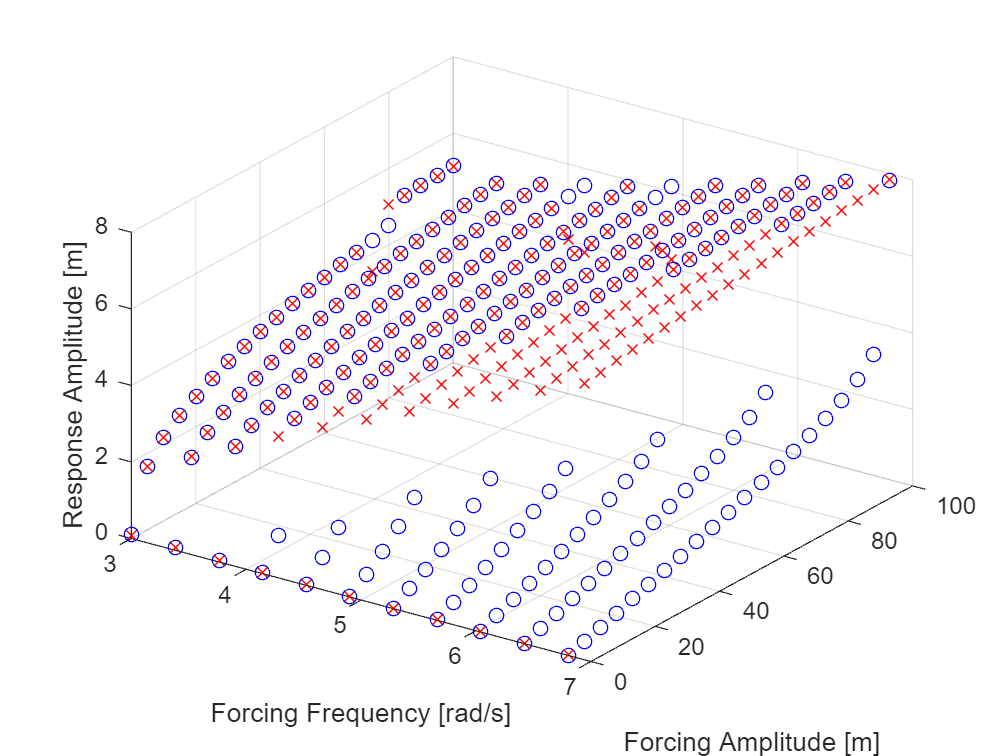

figure;
hold on;
grid on;
for k = (1:length(freq_range))
    y1 = OL_curve{k, 1}(:, 1);          % forcing val
    x1 = ones(size(y1)).*freq_range(k);  % forcing freq
    z1 = OL_curve{k, 1}(:, 2);          % reponse ampl

    y2 = OL_curve{k, 2}(:, 1);          % forcing val
    x2 = ones(size(y2)).*freq_range(k); % forcing freq
    z2 = OL_curve{k, 2}(:, 2);          % reponse ampl

    scatter3(x1, y1, z1, "bo");
    scatter3(x2, y2, z2, "rx");
end
view([35, 35]);
xlabel("Forcing Frequency [rad/s]");
ylabel("Forcing Amplitude [m]");
zlabel("Response Amplitude [m]");

## remove jumps

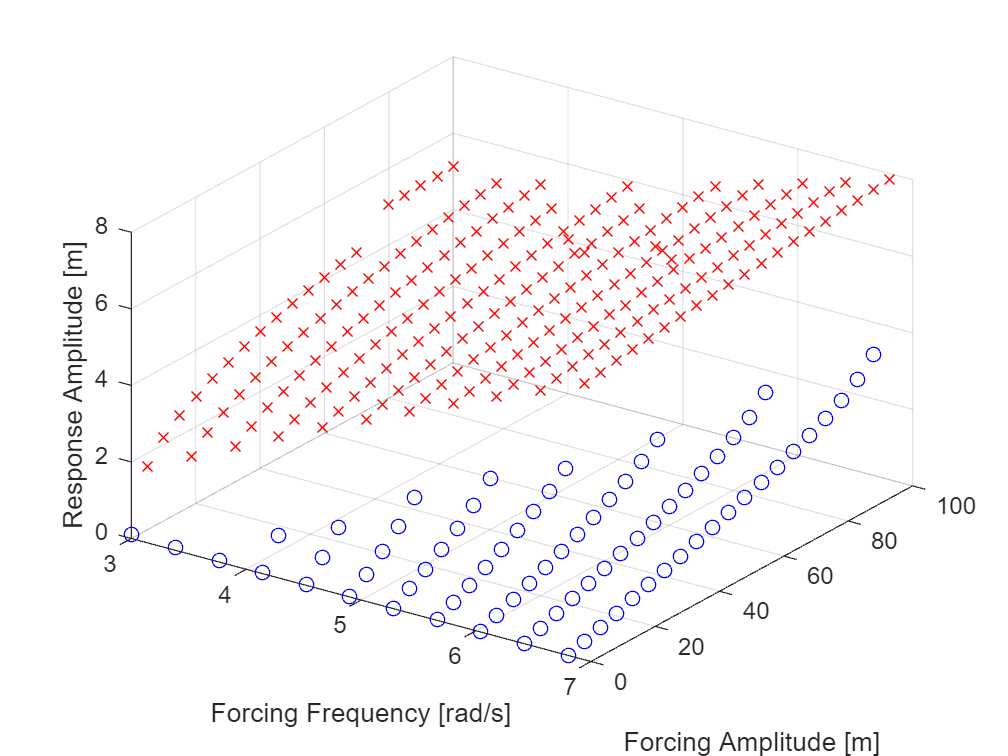

open_cube = {};



figure;
hold on;
grid on;
for k = (1:length(freq_range))
    y1 = OL_curve{k, 1}(:, 1);          % forcing ampl
    x1 = ones(size(y1)).*freq_range(k);  % forcing freq

    z1 = OL_curve{k, 1}(:, 2) ;        % reponse ampl
    z1_delta = z1 - [z1(1); z1(1:end-1)];
    [idx, ~] = find(z1_delta>1);
    z1(idx:end) = [];
    x1(idx:end) = [];
    y1(idx:end) = [];
    
    y2 = OL_curve{k, 2}(:, 1);          % forcing val
    x2 = ones(size(y2)).*freq_range(k); % forcing freq
    z2 = OL_curve{k, 2}(:, 2);          % reponse ampl
    z2_delta = z2 - [z2(1); z2(1:end-1)];
    [idx, ~] = find(z2_delta<-1);
    z2(idx) = [];
    x2(idx) = [];
    y2(idx) = [];



    scatter3(x1, y1, z1, "bo");
    scatter3(x2, y2, z2, "rx");

    curve.frequency = freq_range(k);
    curve.up = [y1, z1];
    curve.down = [y2, z2];
    curve.CL_bounds = [curve.up(end, :); curve.down(end, :)];
    open_cube{k} = curve;
end
view([35, 35]);
xlabel("Forcing Frequency [rad/s]");
ylabel("Forcing Amplitude [m]");
zlabel("Response Amplitude [m]");

## run  harmonizer for open cube bounds and store data in closed cube

% closed_cube = open_cube;
%
% asdfghjdsa
closed_cube{9}.mid

Undefined variable 'closed_cube'.

(length(response_amplitudes):-1:length(response_amplitudes)-6)

target = 5.9132
closed_cube{9}.frequency

closed_cube = load("closed_cube_save.mat").closed_cube;
for j = (9:11)%length(open_cube))
    curve = closed_cube{j};

    w0 = curve.frequency;
    periods = 30;
    dt = 1/1000;
    invasive_tol = 5/100;
    x_init = [0, 0];

    response_amplitudes = linspace(curve.CL_bounds(1, 2), curve.CL_bounds(2, 2), 11)
    forcing_amplitudes = zeros(size(response_amplitudes));
    prev_target = 0;
    next_target = 0;
    
    %reverse
    delta_ra = response_amplitudes(2) - response_amplitudes(1);
    response_amplitudes = [response_amplitudes, response_amplitudes(end) + delta_ra, response_amplitudes(end) + 2*delta_ra];
    forcing_amplitudes = zeros(size(response_amplitudes));

    % for i = (1:length(response_amplitudes))
    counter = 1;
    for i = (length(response_amplitudes):-1:length(response_amplitudes)-7)

        target = response_amplitudes(i)
    
        % reset structures
        [model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
        % if i > 2
        if counter > 2
            control.target_vec = next_target;
        end
        % get non-invasive control at target response amplitude
        % try
        [experiment, input3, trial3, control2, success] = harmonizer(invasive_tol, model, input, trial, control);
        % catch
        %     "SOME ERROR OCCURED||SOME ERROR OCCURED||SOME ERROR OCCURED||SOME ERROR OCCURED||SOME ERROR OCCURED"
        %     sdf
        %     break;
        % end
            %set next x_init to start from last time xd = 0
        [t_lin, x_lin] = get_last_n_periods(trial3.t_span, -trial3.X(:, 2), 3);
        xp = interp1(trial3.t_span, trial3.X(:, 1), t_lin(1));
        x_init = [xp, -x_lin(1)];
        
        if counter > 1
            t1 = control2.target_vec;
            t2 = prev_target

            delta_main = response_amplitudes(i+1)./response_amplitudes(i);
            next_target = (t1-t2).*delta_main;
        end

        prev_target = control.target_vec;

        if success == false %skip if harmonizer fails
            break;
        end

        % get forcing amplitudes
        [~, x_lin] = get_last_n_periods(trial3.t_span, input3.f_history, 10);
        forcing_amplitudes(i) = max(x_lin);
    
        % get actual response amplitude
        [~, x_lin] = get_last_n_periods(trial3.t_span, trial3.X(:, 1), 10);
        response_amplitudes(i) = max(x_lin);

        "s-curve tracker: Iteration number = " + i
        counter = counter + 1;
    end

    % assign to closed_cube
    % closed_cube{j}.mid = [forcing_amplitudes', response_amplitudes'];
    closed_cube{j}.mid = [closed_cube{j}.mid; forcing_amplitudes', response_amplitudes'];
end

response_amplitudes =     2.5051    2.8459    3.1867    3.5275    3.8684    4.2092    4.5500    4.8908    5.2316    5.5724    5.9132


target = 6.5948

Kd = 230.4110

Kp = 230.4110

ans = "get_response_target: response amp -> 6.5883"

ans = "get_response_target: response amp -> 6.5864"

ans = "Harmony Loop: 2 -> invasiveness: 207.9606"

ans =    -2.9965  -32.4902         0    6.5948
    0.2711    6.5639    0.0010    0.0010
   -0.1468  -67.8533    0.0010    0.0010
    0.5853   -1.3504    0.0010    0.0010
   -0.1321   -1.2760    0.0010    0.0010
   -1.0062   -1.3585    0.0010    0.0010
    1.5454    1.6191    0.0010    0.0010


ans = "get_response_target: response amp -> 6.7812"

ans = "Harmony Loop: 3 -> invasiveness: 48.0541"

ans =   -32.2094  -34.0452         0    6.5948
   10.4258    1.9294   -0.0009   -0.1471
   19.0443  -12.0223    0.0008   -0.1931
    1.2402   -3.1736   -0.0002    0.0033
    1.6349    7.1266    0.0008   -0.0012
    0.0406    0.0429   -0.0000   -0.0003
   -0.2997    0.1020    0.0000    0.0001


ans = "get_response_target: response amp -> 6.8286"

ans = "Harmony Loop: 4 -> invasiveness: 31.48"

ans =   -28.5236  -39.3440         0    6.5948
   13.7402    6.7256    0.0011   -0.2087
   11.5558   -3.0028    0.0010   -0.2350
    6.7495   -3.7485    0.0021   -0.0007
   -3.0822    6.4514    0.0010    0.0007
    0.1687    0.1522    0.0000   -0.0002
   -0.4995   -0.0160    0.0002    0.0000


ans = "get_response_target: response amp -> 6.8609"

ans = "Harmony Loop: 5 -> invasiveness: 18.8233"

ans =    -4.0319  -48.7545         0    6.5948
    0.9485    8.0920   -0.0070   -0.1223
    2.1358    8.9574    0.0013   -0.2489
    0.0697   -8.5136   -0.0008    0.0251
    1.0589    6.8216    0.0008    0.0181
    0.0315   -0.8497   -0.0000   -0.0003
   -0.3032    1.0073   -0.0002    0.0000


ans = "get_response_target: response amp -> 6.7085"

ans = "Harmony Loop: 6 -> invasiveness: 496.7401"

ans =   -30.2621   42.5733         0    6.5948
  -43.7564   10.0037   -0.0076   -0.6341
    0.4453   -3.9438    0.0013   -0.2385
  -13.6982  -32.4527   -0.0008   -0.0210
   71.3869 -249.4483    0.0009   -0.3036
    1.1969    0.4956   -0.0000   -0.0002
    9.9098    1.0123   -0.0009    0.0000


ans = "get_response_target: response amp -> 7.6316"

ans = "Harmony Loop: 7 -> invasiveness: 165.1763"

ans =    -5.3090  -87.6897         0    6.5948
   -3.0036 -145.0767   -0.0070    2.0444
    3.3788   -9.6679    0.0013   -0.2416
   -2.3699  -91.9648   -0.0008    0.0415
    0.8944   19.8221    0.0008    0.0096
    0.6748    1.8266   -0.0000   -0.0003
   -0.6206    3.5547   -0.0003    0.0017


ans = "get_response_target: response amp -> 6.8379"

ans = "Harmony Loop: 8 -> invasiveness: 88.2337"

ans =   -40.2189  -29.7371         0    6.5948
   34.9772   -6.4413   -0.0070   -0.4613
    3.4466   -9.5559    0.0013   -0.2363
  -14.4931  -41.6856   -0.0008   -0.0550
   16.8655    7.4388    0.0008   -0.0135
   -1.1718    0.3741   -0.0000   -0.0002
   -0.1670   -1.0845   -0.0003   -0.0006


ans = "get_response_target: response amp -> 6.377"

ans = "Harmony Loop: 9 -> invasiveness: 531.6046"

ans =     9.4625   18.9466         0    6.5948
  -49.5863   10.7483   -0.0070   -0.5778
   70.1521  -88.0555    0.0022    0.2227
    4.1288  -86.1265   -0.0008   -0.1351
   -5.8765   -5.8429    0.0008   -0.0273
    6.4759    0.5758   -0.0000   -0.0002
    0.3168   -0.0016   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.9151"

ans = "Harmony Loop: 10 -> invasiveness: 69.1095"

ans =   -25.2549  -40.1950         0    6.5948
   27.7386   17.5170   -0.0070   -0.5050
   -4.9943   -1.4987    0.0013   -0.2921
   -6.6819    4.9595   -0.0008    0.0200
   12.8206  -20.2351    0.0008   -0.0212
    0.3484   -2.5570   -0.0000   -0.0002
   -0.5026   -0.7002   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.9597"

ans = "Harmony Loop: 11 -> invasiveness: 91.2769"

ans =   -25.5643  -41.2166         0    6.5948
   38.5489   21.7676   -0.0070   -0.6934
    4.0629    0.2788    0.0013   -0.3010
  -14.3215   10.3453   -0.0008    0.0116
   13.1026  -26.8749    0.0008   -0.0298
   -0.3616   -2.7478   -0.0000   -0.0002
   -0.9614   -0.8303   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.9109"

ans = "Harmony Loop: 12 -> invasiveness: 46.3387"

ans =    -3.7090  -51.1244         0    6.5948
    0.0930  -21.0124   -0.0070    0.2714
    1.6861   -4.7023    0.0013   -0.2996
   -0.0884  -23.7525   -0.0008    0.0278
    0.3919   -5.8097    0.0008    0.0049
    0.1710    0.3698   -0.0000   -0.0004
   -0.4229    0.5777   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.9135"

ans = "Harmony Loop: 13 -> invasiveness: 28.1533"

ans =    -3.4383  -51.0132         0    6.5948
    0.8344   14.3703   -0.0070   -0.2025
    1.6691   -4.4201    0.0013   -0.3010
    0.5193   -1.2234   -0.0008    0.0165
    0.6858    2.0601    0.0008    0.0144
    0.0388   -0.7089   -0.0000   -0.0004
   -0.4451    0.7887   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.9249"

ans = "Harmony Loop: 14 -> invasiveness: 18.7291"

ans =    -3.3122  -51.3881         0    6.5948
    0.6070    0.1748   -0.0070   -0.0100
    1.1833   -9.5716   -0.0007   -0.3216
    0.6044   -7.7055   -0.0008    0.0159
    0.6079   -0.9821    0.0008    0.0119
    0.0740   -0.0690   -0.0000   -0.0004
   -0.7420    0.8148   -0.0005   -0.0001


ans = "get_response_target: response amp -> 6.8877"

ans = "Harmony Loop: 15 -> invasiveness: 16.3748"

ans =    -2.7627  -49.9640         0    6.5948
    0.6091   -0.0068   -0.0070   -0.0076
   -0.0102    0.1975   -0.0056   -0.2832
    1.0949   -8.1205   -0.0008    0.0166
    0.3143    1.0611    0.0008    0.0127
    0.0851   -0.0749   -0.0000   -0.0004
   -0.0255    0.3255   -0.0000   -0.0003


ans = "get_response_target: response amp -> 6.8892"

ans = "Harmony Loop: 16 -> invasiveness: 2.2025"

ans =    -2.0056  -50.0217         0    6.5948
    0.5345    0.5226   -0.0069   -0.0077
    0.0123   -0.0094   -0.0055   -0.2840
    0.7311   -0.8254   -0.0008    0.0024
    0.2964    0.7039    0.0008    0.0123
   -0.0336    0.3932   -0.0000   -0.0004
    0.0267    0.0604   -0.0000   -0.0005


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans =    -2.0056  -50.0217         0    6.5948
    0.5345    0.5226   -0.0069   -0.0077
    0.0123   -0.0094   -0.0055   -0.2840
    0.7311   -0.8254   -0.0008    0.0024
    0.2964    0.7039    0.0008    0.0123
   -0.0336    0.3932   -0.0000   -0.0004
    0.0267    0.0604   -0.0000   -0.0005


ans = "s-curve tracker: Iteration number = 13"

target = 6.2540

Kd = 230.4110

Kp = 230.4110

ans = "get_response_target: response amp -> 6.2504"

ans = "get_response_target: response amp -> 6.2485"

ans = "Harmony Loop: 2 -> invasiveness: 427.4463"

ans =    -2.3300  -13.8699         0    6.2540
    0.2640    2.9684    0.0010    0.0010
   -0.1951  -60.1167    0.0010    0.0010
    0.5553   -0.2649    0.0010    0.0010
    0.4039    0.5474    0.0010    0.0010
   -1.0520   -1.1952    0.0010    0.0010
    1.5460    1.6582    0.0010    0.0010


ans = "get_response_target: response amp -> 6.4556"

ans = "Harmony Loop: 3 -> invasiveness: 31.91"

ans =    -1.1978  -24.0623         0    6.2540
   -0.3311    4.1508   -0.0009   -0.0529
   -0.2753    7.6828    0.0007   -0.2056
   -0.1071    0.8787   -0.0002    0.0015
    1.8794   -5.6610    0.0004    0.0003
    0.0332   -0.0211   -0.0000   -0.0001
   -0.0550    0.2605    0.0000    0.0000


ans = "get_response_target: response amp -> 6.441"

ans = "Harmony Loop: 4 -> invasiveness: 58.4686"

ans =    -2.5807  -23.3366         0    6.2540
   -0.1622  -10.8053    0.0001    0.1362
    1.3630   13.6599    0.0016   -0.1822
    0.0181   -4.8011    0.0000    0.0011
    0.8412   -4.6121    0.0012    0.0009
    0.0137    0.3358    0.0000   -0.0001
    0.1224   -0.0689    0.0000   -0.0002


ans = "get_response_target: response amp -> 6.4882"

ans = "Harmony Loop: 5 -> invasiveness: 16.7038"

ans =    -2.5668  -24.9417         0    6.2540
   -0.0916   -0.0112    0.0012   -0.0004
    1.0244   -0.0877    0.0009   -0.2357
   -0.0427   -0.7160   -0.0000    0.0014
    1.4166   -3.9414    0.0018    0.0038
   -0.0336    0.0656    0.0000   -0.0001
    0.1003    0.1919    0.0000   -0.0001


ans = "get_response_target: response amp -> 6.5036"

ans = "Harmony Loop: 6 -> invasiveness: 32.7591"

ans =    -1.5102  -23.8498         0    6.2540
   -0.2117    1.5726    0.0025   -0.0005
    0.1259    1.5002   -0.0013   -0.2354
   -0.1916    0.7351    0.0000    0.0015
    1.6876   -7.6446    0.0003    0.0209
    0.1766   -0.6457    0.0000   -0.0001
    0.4604   -0.8178   -0.0001   -0.0001


ans = "get_response_target: response amp -> 6.4724"

ans = "Harmony Loop: 7 -> invasiveness: 99.7351"

ans =   -20.2326   -3.7863         0    6.2540
    1.1764    0.6301    0.0002   -0.0004
    0.5503   -0.3268   -0.0016   -0.2357
    0.4653    0.5995   -0.0000    0.0014
    8.1605  -18.8377    0.0097   -0.0143
    0.3430   -0.3331    0.0000   -0.0001
    0.6634   -0.1294    0.0000   -0.0001


ans = "get_response_target: response amp -> 6.5278"

ans = "Harmony Loop: 8 -> invasiveness: 122.0554"

ans =   -24.6110    5.2254         0    6.2540
    0.2227   -0.0352    0.0021   -0.0003
   -1.0234    0.5679   -0.0012   -0.2357
   -0.2372   -0.6270    0.0000    0.0013
   27.2968  -14.0680   -0.0022    0.0449
   -0.1417    0.0009    0.0000   -0.0001
   -1.6978    0.3769   -0.0004   -0.0001


ans = "get_response_target: response amp -> 6.7024"

ans = "Harmony Loop: 9 -> invasiveness: 685.2503"

ans =   -24.1607    9.5285         0    6.2540
    0.2226   -0.2122    0.0026   -0.0003
   -4.4431    4.7891   -0.0014   -0.2357
   -0.5678   -0.7992   -0.0000    0.0014
   20.6505 -176.7694    0.0148    0.2195
   -0.1156    0.7161    0.0000   -0.0001
    2.0561    6.9781   -0.0001   -0.0001


ans = "get_response_target: response amp -> 5.637"

ans = "Harmony Loop: 10 -> invasiveness: 254.4125"

ans =   -21.8058   14.3910         0    6.2540
   36.0382  -55.8514    1.0013   -0.0003
   -1.5186   12.6545   -0.0011   -0.2357
  -15.4370  -18.3224    0.0000    0.0011
   37.6977  -39.8173    0.0675    0.0298
   -1.7978   -1.3372    0.0000   -0.0001
   -0.1684    1.2842   -0.0003   -0.0001


ans = "get_response_target: response amp -> 6.461"

ans = "Harmony Loop: 11 -> invasiveness: 201.0251"

ans =   -17.7924   17.5739         0    6.2540
   -0.0001    0.2482   -0.0036   -0.0003
   -1.3253   -0.6780   -0.0009   -0.2357
   -0.3117    0.4466   -0.0000    0.0014
   16.5619  -47.4664   -0.0491   -0.0253
    0.0068    0.2349    0.0000   -0.0001
    1.8373    0.8848   -0.0002   -0.0001


ans = "get_response_target: response amp -> 6.8104"

ans = "Harmony Loop: 12 -> invasiveness: 1062.113"

ans =   -23.9297   12.1933         0    6.2540
   -0.1750    0.1566   -0.0036   -0.0003
   -7.9313    6.5447    0.0002   -0.2357
   -0.6652   -0.4237   -0.0000    0.0014
   15.5205 -284.8306   -0.1405    0.3169
   -0.0635    0.3934    0.0000   -0.0001
    6.1492    9.4356   -0.0003   -0.0001


ans = "get_response_target: response amp -> 7.5761"

ans = "Harmony Loop: 13 -> invasiveness: 2770.799"

ans = 1.0e+03 *

   -0.0367    0.0271         0    0.0063
   -0.0000   -0.0006   -0.0000   -0.0000
   -0.0456    0.0073   -0.0000   -0.0002
   -0.0003   -0.0035   -0.0000    0.0000
   -0.0228   -1.2646   -0.0015   -0.0001
    0.0004    0.0050    0.0000   -0.0000
    0.0442    0.0200   -0.0000   -0.0000


ans = "get_response_target: response amp -> 7.1561"

ans = "Harmony Loop: 14 -> invasiveness: 2127.3002"

ans =   -27.4388   16.8207         0    6.2540
   -0.0965    0.1088   -0.0036   -0.0003
  -22.4575   10.3753    0.0005   -0.2357
   -0.6163   -0.4857   -0.0000    0.0014
    6.7672 -684.6201   -0.6923    0.4363
    0.0161    0.9201    0.0000   -0.0001
   20.4950   16.5189   -0.0003   -0.0001


ans = "get_response_target: response amp -> 7.7761"

ans = "Harmony Loop: 15 -> invasiveness: 2561.3539"

ans = 1.0e+03 *

   -0.0400    0.0206         0    0.0063
   -0.0001   -0.0000   -0.0000   -0.0000
   -0.0352    0.0233    0.0000   -0.0002
   -0.0006   -0.0011   -0.0000    0.0000
   -0.0126   -1.1523   -0.0009    0.0011
    0.0000    0.0015    0.0000   -0.0000
    0.0315    0.0312   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.7783"

ans = "Harmony Loop: 16 -> invasiveness: 2418.6515"

ans =   -22.2872   22.0297         0    6.2540
    0.0284    0.1329   -0.0036   -0.0003
  -27.9586   -0.8154   -0.0024   -0.2356
   -0.1676   -0.1133    0.0000    0.0014
   -8.8852 -757.8886   -0.7572   -0.4797
    0.1229    0.9602    0.0000   -0.0001
   27.7689    5.3747   -0.0002   -0.0001


ans = "get_response_target: response amp -> 8.5833"

ans = "Harmony Loop: 17 -> invasiveness: 2253.942"

ans = 1.0e+03 *

   -0.0726    0.1063         0    0.0063
    0.0002   -0.0004   -0.0000   -0.0000
   -0.0987   -0.0382   -0.0000   -0.0002
    0.0004   -0.0024    0.0000    0.0000
   -0.0726   -2.8998   -0.0005   -0.0034
    0.0003    0.0035    0.0000   -0.0000
    0.1040   -0.0184    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3263"

ans = "Harmony Loop: 18 -> invasiveness: 2333.9242"

ans =   -30.3536   17.6409         0    6.2540
   -0.0907   -0.2896   -0.0036   -0.0003
  -25.5452   12.7094    0.0046   -0.2356
   -0.5417   -2.3988    0.0000    0.0014
   -2.7828 -819.3808   -0.7977    0.5685
    0.1604    3.2945    0.0000   -0.0001
   24.4348   21.2438   -0.0004   -0.0001


ans = "get_response_target: response amp -> 8.7444"

ans = "Harmony Loop: 19 -> invasiveness: 2436.0031"

ans = 1.0e+03 *

   -0.0721    0.0316         0    0.0063
   -0.0001   -0.0002   -0.0000   -0.0000
   -0.0517    0.0483    0.0000   -0.0002
   -0.0006   -0.0021    0.0000    0.0000
   -0.0221   -1.9170   -0.0008    0.0021
    0.0001    0.0024    0.0000   -0.0000
    0.0453    0.0586   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8162"

ans = "Harmony Loop: 20 -> invasiveness: 2577.3072"

ans =   -23.0123   23.5235         0    6.2540
    0.0433    0.1144   -0.0036   -0.0003
  -31.4975   -1.7834   -0.0038   -0.2356
   -0.1255   -0.1566   -0.0000    0.0015
  -11.7293 -848.0531   -0.7958   -0.6107
    0.1332    1.0614    0.0000   -0.0001
   31.1141    4.8997   -0.0002   -0.0001


ans = "get_response_target: response amp -> 8.0758"

ans = "Harmony Loop: 21 -> invasiveness: 2531.0956"

ans = 1.0e+03 *

   -0.0567    0.0777         0    0.0063
    0.0001   -0.0014   -0.0000   -0.0000
   -0.0867   -0.0262   -0.0000   -0.0002
    0.0005   -0.0070   -0.0000    0.0000
   -0.0608   -2.4337   -0.0008   -0.0028
    0.0009    0.0093    0.0000   -0.0000
    0.0884   -0.0062    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3237"

ans = "Harmony Loop: 22 -> invasiveness: 2328.6848"

ans =   -30.3999   17.4791         0    6.2540
   -0.0736   -0.2856   -0.0036   -0.0003
  -23.7730   12.5645    0.0114   -0.2356
   -0.5557   -2.3810   -0.0000    0.0015
    4.0842 -816.5822   -0.7999    0.5599
    0.1380    3.2847    0.0000   -0.0001
   24.3028   21.7885   -0.0006   -0.0001


ans = "get_response_target: response amp -> 8.8458"

ans = "Harmony Loop: 23 -> invasiveness: 2403.4213"

ans = 1.0e+03 *

   -0.0763    0.0328         0    0.0063
   -0.0001   -0.0011   -0.0000   -0.0000
   -0.0500    0.0509    0.0000   -0.0002
   -0.0005   -0.0065   -0.0000    0.0000
   -0.0349   -1.9967   -0.0008    0.0023
    0.0005    0.0080    0.0000   -0.0000
    0.0469    0.0647   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8211"

ans = "Harmony Loop: 24 -> invasiveness: 2582.8409"

ans =   -23.1062   23.5618         0    6.2540
    0.0432    0.1109   -0.0036   -0.0003
  -31.4789   -1.9411   -0.0029   -0.2356
   -0.1403   -0.1611   -0.0000    0.0015
  -11.6971 -852.2781   -0.7998   -0.6138
    0.1337    1.0659    0.0000   -0.0001
   31.1813    5.0006   -0.0001   -0.0001


ans = "get_response_target: response amp -> 8.0224"

ans = "Harmony Loop: 25 -> invasiveness: 2542.8303"

ans = 1.0e+03 *

   -0.0546    0.0771         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0882   -0.0187   -0.0001   -0.0002
    0.0003   -0.0018   -0.0000    0.0000
   -0.0528   -2.4016   -0.0008   -0.0028
    0.0003    0.0029    0.0000   -0.0000
    0.0869   -0.0074    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3305"

ans = "Harmony Loop: 26 -> invasiveness: 2316.3357"

ans =   -30.6390   17.4956         0    6.2540
   -0.0934    0.0755   -0.0036   -0.0003
  -20.0112   13.8152    0.0254   -0.2356
   -0.6792   -0.6404   -0.0000    0.0015
  -10.1349 -817.1958   -0.7996    0.5619
    0.0421    1.0840    0.0000   -0.0001
   25.0651   21.0733   -0.0011   -0.0001


ans = "get_response_target: response amp -> 8.8633"

ans = "Harmony Loop: 27 -> invasiveness: 2394.0402"

ans = 1.0e+03 *

   -0.0771    0.0329         0    0.0063
   -0.0001   -0.0011   -0.0000   -0.0000
   -0.0450    0.0537    0.0000   -0.0002
   -0.0005   -0.0066   -0.0000    0.0000
   -0.0391   -2.0080   -0.0008    0.0023
    0.0005    0.0080    0.0000   -0.0000
    0.0461    0.0672   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8293"

ans = "Harmony Loop: 28 -> invasiveness: 2574.0973"

ans =   -23.3728   23.3507         0    6.2540
    0.0436    0.1129   -0.0036   -0.0003
  -29.5486   -3.4276    0.0067   -0.2356
   -0.1589   -0.1595   -0.0001    0.0015
  -13.4747 -850.3368   -0.7997   -0.6108
    0.1342    1.0633    0.0000   -0.0001
   30.6566    5.3480    0.0002   -0.0001


ans = "get_response_target: response amp -> 7.9806"

ans = "Harmony Loop: 29 -> invasiveness: 2554.6826"

ans = 1.0e+03 *

   -0.0530    0.0768         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0897   -0.0145   -0.0001   -0.0002
    0.0003   -0.0017   -0.0000    0.0000
   -0.0580   -2.3826   -0.0008   -0.0027
    0.0003    0.0029    0.0000   -0.0000
    0.0858   -0.0022    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3398"

ans = "Harmony Loop: 30 -> invasiveness: 2305.923"

ans =   -31.0396   17.1461         0    6.2540
   -0.0903    0.0789   -0.0036   -0.0003
  -14.5115   14.2240    0.0463   -0.2356
   -0.6902   -0.6540   -0.0001    0.0015
  -11.8163 -817.6051   -0.7996    0.5638
    0.0458    1.0872    0.0000   -0.0001
   26.0054   23.4237   -0.0025   -0.0001


ans = "get_response_target: response amp -> 8.8776"

ans = "Harmony Loop: 31 -> invasiveness: 2385.9039"

ans = 1.0e+03 *

   -0.0778    0.0331         0    0.0063
   -0.0001   -0.0011   -0.0000   -0.0000
   -0.0400    0.0564    0.0001   -0.0002
   -0.0006   -0.0066   -0.0000    0.0000
   -0.0432   -2.0175   -0.0008    0.0023
    0.0005    0.0081    0.0000   -0.0000
    0.0435    0.0732   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8534"

ans = "Harmony Loop: 32 -> invasiveness: 2552.2475"

ans =   -24.1458   22.8302         0    6.2540
    0.0462    0.1108   -0.0036   -0.0003
  -24.3688   -7.6156    0.0331   -0.2356
   -0.1781   -0.1548   -0.0001    0.0015
  -14.9405 -847.9817   -0.7996   -0.6077
    0.1292    1.0638    0.0000   -0.0001
   27.5382    7.7262    0.0025   -0.0001


ans = "get_response_target: response amp -> 8.0073"

ans = "Harmony Loop: 33 -> invasiveness: 2557.6956"

ans = 1.0e+03 *

   -0.0545    0.0747         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0837   -0.0241   -0.0000   -0.0002
    0.0003   -0.0017   -0.0000    0.0000
   -0.0611   -2.3632   -0.0008   -0.0027
    0.0003    0.0029    0.0000   -0.0000
    0.0842    0.0190    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3436"

ans = "Harmony Loop: 34 -> invasiveness: 2301.6272"

ans =   -31.2302   16.9828         0    6.2540
   -0.0879    0.0789   -0.0036   -0.0003
  -11.8266   14.4310    0.0565   -0.2356
   -0.6979   -0.6644   -0.0001    0.0015
  -13.0176 -818.1052   -0.7996    0.5653
    0.0501    1.0926    0.0000   -0.0001
   27.4117   26.6428   -0.0045   -0.0001


ans = "get_response_target: response amp -> 8.8865"

ans = "Harmony Loop: 35 -> invasiveness: 2379.9299"

ans = 7×4
1.0e+03 *

   -0.0783    0.0337         0    0.0063
   -0.0001   -0.0003   -0.0000   -0.0000
   -0.0405    0.0583    0.0001   -0.0002
   -0.0006   -0.0023   -0.0000    0.0000
   -0.0163   -2.0289   -0.0008    0.0023
    0.0001    0.0026    0.0000   -0.0000
    0.0353    0.0852   -0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8906"

ans = "Harmony Loop: 36 -> invasiveness: 2516.3332"

ans = 7×4
  -24.9967   22.4272         0    6.2540
    0.0482    0.1377   -0.0038   -0.0003
  -20.2385  -11.0720    0.0510   -0.2356
   -0.2083   -0.1553   -0.0001    0.0015
   34.5187 -844.3535   -0.7997   -0.6042
    0.0004    1.1022    0.0000   -0.0001
  -15.7295   35.6437    0.0316   -0.0001


ans = "get_response_target: response amp -> 8.0386"

ans = "Harmony Loop: 37 -> invasiveness: 2562.4877"

ans = 7×4
1.0e+03 *

   -0.0562    0.0719         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0770   -0.0346    0.0000   -0.0002
    0.0002   -0.0017   -0.0000    0.0000
   -0.0663   -2.3370   -0.0008   -0.0027
    0.0003    0.0028    0.0000   -0.0000
    0.0835    0.0210    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3724"

ans = "Harmony Loop: 38 -> invasiveness: 2285.6027"

ans = 7×4
  -31.6305   16.6740         0    6.2540
   -0.0893   -0.2815   -0.0039   -0.0003
  -11.9073   13.8401    0.0577   -0.2356
   -0.6672   -2.5121   -0.0001    0.0015
   -1.3567 -817.2459   -0.7996    0.5652
    0.0530    3.0712    0.0000   -0.0001
    4.4140  -24.7428    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.9126"

ans = "Harmony Loop: 39 -> invasiveness: 2372.5658"

ans = 7×4
1.0e+03 *

   -0.0792    0.0330         0    0.0063
   -0.0000   -0.0011   -0.0000   -0.0000
   -0.0429    0.0562    0.0001   -0.0002
   -0.0005   -0.0068   -0.0000    0.0000
   -0.0506   -2.0352   -0.0008    0.0023
    0.0007    0.0079    0.0000   -0.0000
    0.0704    0.0186    0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8928"

ans = "Harmony Loop: 40 -> invasiveness: 2520.3397"

ans = 7×4
  -25.0639   22.2027         0    6.2540
    0.0494   -0.2702   -0.0038   -0.0003
  -19.3310  -12.3665    0.0559   -0.2356
   -0.1498   -1.9085   -0.0002    0.0015
   20.8184 -843.6475   -0.7996   -0.6028
   -0.0364    3.4239    0.0000   -0.0001
  -11.6467   35.0355    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.0445"

ans = "Harmony Loop: 41 -> invasiveness: 2559.6434"

ans = 7×4
1.0e+03 *

   -0.0566    0.0713         0    0.0063
    0.0002   -0.0002   -0.0000   -0.0000
   -0.0746   -0.0383    0.0001   -0.0002
    0.0002   -0.0016   -0.0000    0.0000
   -0.0675   -2.3291   -0.0008   -0.0027
    0.0003    0.0029    0.0000   -0.0000
    0.0821    0.0420    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3736"

ans = "Harmony Loop: 42 -> invasiveness: 2286.3906"

ans = 7×4
  -31.6509   16.6838         0    6.2540
   -0.0881   -0.2893   -0.0038   -0.0003
  -11.9022   13.8921    0.0577   -0.2356
   -0.6785   -2.5269   -0.0002    0.0015
   -2.5029 -818.0419   -0.7996    0.5669
    0.0588    3.0753    0.0000   -0.0001
    4.4876  -24.7037    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.9203"

ans = "Harmony Loop: 43 -> invasiveness: 2370.3454"

ans = 7×4
1.0e+03 *

   -0.0795    0.0332         0    0.0063
   -0.0001   -0.0011   -0.0000   -0.0000
   -0.0438    0.0561    0.0001   -0.0002
   -0.0005   -0.0068   -0.0000    0.0000
   -0.0532   -2.0423   -0.0008    0.0023
    0.0007    0.0079    0.0000   -0.0000
    0.0702    0.0198    0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8939"

ans = "Harmony Loop: 44 -> invasiveness: 2517.833"

ans = 7×4
  -25.0954   22.1673         0    6.2540
    0.0481   -0.2673   -0.0038   -0.0003
  -19.0415  -12.5333    0.0572   -0.2356
   -0.1681   -1.9074   -0.0002    0.0015
   19.7725 -842.8342   -0.7996   -0.6012
   -0.0352    3.4196    0.0000   -0.0001
  -11.6834   35.0129    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.0401"

ans = "Harmony Loop: 45 -> invasiveness: 2563.7074"

ans = 7×4
1.0e+03 *

   -0.0565    0.0707         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0738   -0.0391    0.0001   -0.0002
    0.0002   -0.0016   -0.0000    0.0000
   -0.0699   -2.3195   -0.0008   -0.0027
    0.0003    0.0029    0.0000   -0.0000
    0.0818    0.0419    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3746"

ans = "Harmony Loop: 46 -> invasiveness: 2282.9153"

ans = 7×4
  -31.7154   16.7635         0    6.2540
   -0.0991    0.0882   -0.0038   -0.0003
  -12.0640   14.5869    0.0577   -0.2356
   -0.7125   -0.7604   -0.0002    0.0015
    8.8163 -818.9065   -0.7996    0.5684
   -0.0058    0.9916    0.0000   -0.0001
    5.0424  -25.7682    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.9293"

ans = "Harmony Loop: 47 -> invasiveness: 2367.2693"

ans = 7×4
1.0e+03 *

   -0.0799    0.0334         0    0.0063
   -0.0001   -0.0011   -0.0000   -0.0000
   -0.0442    0.0563    0.0001   -0.0002
   -0.0005   -0.0069   -0.0000    0.0000
   -0.0561   -2.0499   -0.0008    0.0023
    0.0007    0.0079    0.0000   -0.0000
    0.0705    0.0200    0.0000   -0.0000


ans = "get_response_target: response amp -> 6.8941"

ans = "Harmony Loop: 48 -> invasiveness: 2516.5619"

ans = 7×4
  -25.1001   22.1539         0    6.2540
    0.0468   -0.2673   -0.0038   -0.0003
  -18.9548  -12.5597    0.0576   -0.2356
   -0.1800   -1.9062   -0.0002    0.0015
   19.0458 -842.2923   -0.7996   -0.6001
   -0.0515    3.4134    0.0000   -0.0001
  -11.6957   34.9843    0.0293   -0.0001


ans = "get_response_target: response amp -> 8.0334"

ans = "Harmony Loop: 49 -> invasiveness: 2567.8661"

ans = 7×4
1.0e+03 *

   -0.0563    0.0703         0    0.0063
    0.0001   -0.0002   -0.0000   -0.0000
   -0.0734   -0.0392    0.0001   -0.0002
    0.0002   -0.0016   -0.0000    0.0000
   -0.0720   -2.3115   -0.0008   -0.0026
    0.0003    0.0029    0.0000   -0.0000
    0.0815    0.0419    0.0000   -0.0000


ans = "get_response_target: response amp -> 7.3755"

ans = "Harmony Loop: 50 -> invasiveness: 2283.51"

ans = 7×4
  -31.7281   16.7711         0    6.2540
   -0.0990    0.0873   -0.0038   -0.0003
  -12.0720   14.6223    0.0577   -0.2356
   -0.7159   -0.7685   -0.0002    0.0015
    8.0376 -819.4659   -0.7996    0.5695
   -0.0103    1.0412    0.0000   -0.0001
    5.0778  -25.7767    0.0293   -0.0001


ans = "%%%%%%%%%%%%%%%%%%%%%%%%%%%% COULDNT CONVERGE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%"

t2 = 7×2
         0    6.5948
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


response_amplitudes = 1×11
    3.1192    3.4466    3.7741    4.1015    4.4289    4.7563    5.0838    5.4112    5.7386    6.0661    6.3935


target = 7.0483

Kd = 244.9259

Kp = 244.9259

ans = "get_response_target: response amp -> 7.0424"

ans = "get_response_target: response amp -> 7.0406"

ans = "Harmony Loop: 2 -> invasiveness: 245.8376"

ans = 7×4
   -3.3921  -33.9227         0    7.0483
    0.3308    6.9804    0.0010    0.0010
   -0.3493  -83.8100    0.0010    0.0010
    0.6633   -1.4064    0.0010    0.0010
   -0.1048   -1.3485    0.0010    0.0010
   -1.1680   -1.5175    0.0010    0.0010
    1.7642    1.8314    0.0010    0.0010


ans = "get_response_target: response amp -> 7.2572"

ans = "Harmony Loop: 3 -> invasiveness: 50.6715"

ans = 7×4
  -37.6223  -34.2143         0    7.0483
   13.6268    0.4991   -0.0010   -0.1660
   18.3182  -18.1229    0.0007   -0.2144
    0.4159   -4.7687   -0.0002    0.0031
    5.1155    7.5915    0.0008   -0.0012
    0.1379    0.0390   -0.0000   -0.0002
   -0.2501    0.2887    0.0000    0.0001


ans = "get_response_target: response amp -> 7.315"

ans = "Harmony Loop: 4 -> invasiveness: 27.9636"

ans = 7×4
   -5.4370  -53.1100         0    7.0483
    1.1261   14.8866    0.0010   -0.1789
    2.8183    8.4483    0.0010   -0.2739
    2.1307    6.8728   -0.0023    0.0001
   -0.8085   -9.7457    0.0010    0.0007
   -0.0936   -0.1945    0.0001   -0.0002
    0.3966    0.1874    0.0001   -0.0001


ans = "get_response_target: response amp -> 7.2974"

ans = "Harmony Loop: 5 -> invasiveness: 27.0955"

ans = 7×4
    1.9727  -52.5036         0    7.0483
   -2.9260   13.3949    0.0012   -0.1656
   -2.5873   13.9991    0.0011   -0.2550
   -2.5795    4.9005    0.0003    0.0019
    5.7985   -8.1859    0.0010   -0.0004
    0.0367   -0.1947    0.0000   -0.0002
    0.4403   -0.1721    0.0001   -0.0004


ans = "get_response_target: response amp -> 7.3375"

ans = "Harmony Loop: 6 -> invasiveness: 49.5383"

ans = 7×4
   20.2505  -47.2139         0    7.0483
   -2.4420    5.6515    0.0011   -0.0461
    1.0562    3.4682    0.0010   -0.3026
   -0.1712    1.1758   -0.0012    0.0062
  -11.1415   -8.6615    0.0010   -0.0058
  -11.7915  -22.5530    0.0000    0.0178
    0.8498   -1.1480    0.0008   -0.0002


ans = "get_response_target: response amp -> 7.451"

ans = "Harmony Loop: 7 -> invasiveness: 136.5077"

ans = 7×4
  -54.1549   11.3237         0    7.0483
    1.1770    3.5808    0.0004    0.0411
    0.9398    1.1781    0.0010   -0.3183
   -2.3190   -5.6101   -0.0013    0.0076
   57.1521  -49.3718    0.0010    0.0931
   -0.5754   -0.0278    0.0000   -0.0004
   -3.4989    1.9931   -0.0008   -0.0004


ans = "get_response_target: response amp -> 7.3509"

ans = "Harmony Loop: 8 -> invasiveness: 68.0435"

ans = 7×4
  -34.1624   43.8639         0    7.0483
   16.1836   -2.0583    0.0007    0.1919
   -4.9839   -6.0178    0.0011   -0.3264
    1.9760   11.3670   -0.0012    0.0064
   18.7453  -32.8599    0.0010   -0.0268
    0.8546   -0.3662    0.0000   -0.0004
    0.5654    1.5149    0.0005   -0.0003


ans = "get_response_target: response amp -> 7.1225"

ans = "Harmony Loop: 9 -> invasiveness: 478.5013"

ans = 7×4
  -29.5644   46.2890         0    7.0483
   10.8695   -3.7581    0.0004    0.1369
  -13.1756   -8.3055    0.0010   -0.3197
    5.1787    7.7205   -0.0012    0.0072
    8.8151 -262.6674    0.0010   -0.2655
    0.1862    0.8108    0.0000   -0.0004
   10.0829   -0.1651    0.0003    0.0000


ans = "get_response_target: response amp -> 7.4074"

ans = "Harmony Loop: 10 -> invasiveness: 38.9132"

ans = 7×4
   -4.2727  -56.6345         0    7.0483
   -0.6458  -22.0915   -0.0001    0.2586
    1.5116  -11.4652    0.0011   -0.3442
    0.0319  -15.5747   -0.0011    0.0088
    0.5936   -6.1892    0.0010    0.0073
    0.1507    1.1887    0.0000   -0.0004
    1.1189    0.8818    0.0005    0.0000


ans = "get_response_target: response amp -> 7.313"

ans = "Harmony Loop: 11 -> invasiveness: 28.2098"

ans = 7×4
   -5.2598  -52.1603         0    7.0483
   -0.5830   -9.5833   -0.0000    0.1119
    3.2630   14.4245    0.0011   -0.2552
   -0.3685   -8.8882   -0.0011    0.0077
    1.2697    3.2270    0.0010    0.0139
    0.1357    0.5102    0.0000   -0.0004
    1.2436    0.7518    0.0005    0.0000


ans = "get_response_target: response amp -> 7.3555"

ans = "Harmony Loop: 12 -> invasiveness: 6.6899"

ans = 7×4
   -4.2784  -54.2553         0    7.0483
    0.0420   -0.2082    0.0002   -0.0004
    1.9282    0.3466    0.0011   -0.3048
    0.4556   -3.6123   -0.0011    0.0063
    0.8212   -0.8493    0.0010    0.0116
    0.0251    0.2036    0.0000   -0.0003
    0.7401    1.3166    0.0003    0.0002


ans = "get_response_target: response amp -> 7.3577"

ans = "Harmony Loop: 13 -> invasiveness: 5.4957"

ans = 7×4
   -3.9278  -54.3366         0    7.0483
    0.0477    0.0407    0.0002   -0.0029
    1.9199    0.0542    0.0012   -0.3060
    0.5628   -2.9406   -0.0011    0.0053
    0.8490   -0.4464    0.0010    0.0121
    0.0117    0.1974    0.0000   -0.0003
   -0.0022    0.6296   -0.0000   -0.0002


ans = "get_response_target: response amp -> 7.359"

ans = "Harmony Loop: 14 -> invasiveness: 6.4851"

ans = 7×4
   -5.4616  -54.2010         0    7.0483
    0.0351    0.1792    0.0003   -0.0025
    3.5143   -0.3607    0.0068   -0.3062
    0.5444   -0.6178   -0.0011    0.0011
    1.1138   -0.1563    0.0010    0.0126
   -0.1863   -0.7910    0.0000    0.0006
   -0.0507   -0.0356   -0.0000   -0.0005


ans = "get_response_target: response amp -> 7.3591"

ans = "Harmony Loop: 15 -> invasiveness: 1.2103"

ans = 7×4
   -1.0334  -54.4909         0    7.0483
   -0.0419    0.2667    0.0007   -0.0030
   -0.0528    0.1123   -0.0056   -0.3060
    0.5880    0.2990   -0.0012   -0.0001
    0.3861    0.4170    0.0009    0.0129
   -0.0618    0.1645    0.0000   -0.0001
   -0.0053   -0.0036   -0.0000   -0.0005


ans = "~~~~~~~~~~~~~~~~~~~~~~~~~~ Non-invasive control achieved! ~~~~~~~~~~~~~~~~~~~~~~~~~~"

ans = 7×4
   -1.0334  -54.4909         0    7.0483
   -0.0419    0.2667    0.0007   -0.0030
   -0.0528    0.1123   -0.0056   -0.3060
    0.5880    0.2990   -0.0012   -0.0001
    0.3861    0.4170    0.0009    0.0129
   -0.0618    0.1645    0.0000   -0.0001
   -0.0053   -0.0036   -0.0000   -0.0005


ans = "s-curve tracker: Iteration number = 13"

target = 6.7209

Kd = 244.9259

Kp = 244.9259

ans = "get_response_target: response amp -> 6.7176"

ans = "get_response_target: response amp -> 6.7157"

ans = "Harmony Loop: 2 -> invasiveness: 533.0664"

ans = 7×4
   -2.6655  -13.8084         0    6.7209
    0.3139    3.0269    0.0010    0.0010
   -0.4878  -74.9652    0.0010    0.0010
    0.6285   -0.2493    0.0010    0.0010
    0.4259    0.6376    0.0010    0.0010
   -1.2072   -1.3442    0.0010    0.0010
    1.7421    1.8251    0.0010    0.0010


ans = "get_response_target: response amp -> 6.9491"

ans = "Harmony Loop: 3 -> invasiveness: 29.9955"

ans = 7×4
   -1.7666  -26.0475         0    6.7209
   -0.2542    4.9551   -0.0010   -0.0558
    0.0885    7.8305    0.0005   -0.2319
   -0.0972    1.1952   -0.0002    0.0014
    1.9422   -7.5851    0.0005    0.0003
    0.0413   -0.0286   -0.0000   -0.0001
   -0.0388    0.3583    0.0000    0.0000


ans = "get_response_target: response amp -> 6.9322"

ans = "Harmony Loop: 4 -> invasiveness: 56.3695"

ans = 7×4
   -2.7188  -25.1848         0    6.7209
    0.0281   -8.0865   -0.0001    0.0901
    0.8769   14.2521    0.0006   -0.2099
    0.1618   -3.8614   -0.0000    0.0011
    1.1536   -6.3387    0.0012    0.0009
   -0.0046    0.3216    0.0000   -0.0001
    0.1332   -0.1181    0.0000   -0.0002


ans = "get_response_target: response amp -> 6.9802"

ans = "Harmony Loop: 5 -> invasiveness: 19.6141"

ans = 7×4
   -3.2937  -26.9204         0    6.7209
    0.0260   -0.0148   -0.0002   -0.0003
    1.0590   -0.0136    0.0005   -0.2588
    0.0186   -0.7537   -0.0001    0.0013
    1.5674   -5.0834    0.0022    0.0044
    0.0075    0.0891    0.0000   -0.0001
    0.1475    0.2154    0.0000   -0.0001


ans = "get_response_target: response amp -> 6.9944"

ans = "Harmony Loop: 6 -> invasiveness: 30.9153"

ans = 7×4
    7.0531  -26.2244         0    6.7209
    0.0981    0.0866   -0.0013   -0.0005
   -0.0240    1.1443    0.0010   -0.2587
    0.7816    0.0335   -0.0001    0.0014
   -7.5628   -3.6452   -0.0017    0.0182
   -0.0506   -0.0435    0.0000   -0.0001
   -0.5638   -0.3894    0.0002   -0.0002


ans = "get_response_target: response amp -> 7.0283"

ans = "Harmony Loop: 7 -> invasiveness: 152.789"

ans = 7×4
  -26.3114    7.0596         0    6.7209
    0.0806   -0.0170    0.0002   -0.0004
   -1.0830    1.6481    0.0010   -0.2588
   -0.2889   -0.7804   -0.0001    0.0014
   28.0624  -30.7402    0.0015    0.0533
   -0.1697    0.1036    0.0000   -0.0001
   -0.9448    1.8088    0.0000   -0.0002


ans = "get_response_target: response amp -> 6.9821"

ans = "Harmony Loop: 8 -> invasiveness: 14.2856"

ans = 7×4
    4.1965  -26.8124         0    6.7209
   -0.5747   -0.3290    0.0072   -0.0004
    0.4673    1.0252    0.0010   -0.2586
    0.5744   -0.5699   -0.0001    0.0014
   -3.8751    0.1198   -0.0010    0.0135
   -0.0695    0.0185    0.0000   -0.0001
   -0.6299    0.5621    0.0004   -0.0002


ans = "get_response_target: response amp -> 6.9874"

ans = "Harmony Loop: 9 -> invasiveness: 14.6357"

ans = 7×4
    3.1579  -26.9448         0    6.7209
   -0.0774   -0.0491    0.0011   -0.0004
    0.5398    1.0322    0.0010   -0.2584
    0.6213   -0.4811   -0.0001    0.0014
   -3.7816    1.2103   -0.0007    0.0136
   -0.0684    0.0159    0.0000   -0.0001
   -0.4091    2.0336    0.0011   -0.0002


ans = "get_response_target: response amp -> 7.0256"

ans = "Harmony Loop: 10 -> invasiveness: 39.8833"

ans = 7×4
   -7.6882  -27.5088         0    6.7209
   -0.0076   -0.0175    0.0001   -0.0004
   -3.8659   -9.5720    0.0010   -0.2950
   -0.4640   -0.6672   -0.0001    0.0014
    8.9920   -6.9941    0.0116    0.0135
   -0.0188    0.1642    0.0001   -0.0001
    2.2825   -4.3832    0.0023   -0.0002


ans = "get_response_target: response amp -> 6.9921"

ans = "Harmony Loop: 11 -> invasiveness: 17.2561"

ans = 7×4
   -6.8860  -26.3839         0    6.7209
    0.0051   -0.0125    0.0000   -0.0004
    0.8218   -1.0148    0.0010   -0.2619
   -0.3610   -0.6401   -0.0001    0.0013
    4.6417    0.7715    0.0029    0.0136
   -0.0686    0.2099    0.0002   -0.0001
    1.6589   -1.9614    0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9879"

ans = "Harmony Loop: 12 -> invasiveness: 26.4705"

ans = 7×4
    4.7178  -26.7016         0    6.7209
   -0.0574    0.0808    0.0001   -0.0004
    0.1642    1.0210    0.0010   -0.2580
   -0.9065    0.5001   -0.0001   -0.0017
   -4.9107   -5.2347   -0.0063    0.0136
   -0.1481   -0.1564    0.0001   -0.0001
    0.8103   -3.2302   -0.0016   -0.0002


ans = "get_response_target: response amp -> 6.9907"

ans = "Harmony Loop: 13 -> invasiveness: 30.874"

ans = 7×4
  -13.5880  -23.5474         0    6.7209
    0.0504    0.0381    0.0000   -0.0004
    0.3353   -0.9854    0.0010   -0.2600
    0.2612   -0.1121   -0.0002   -0.0004
    4.1141   -0.5188   -0.0015    0.0136
    0.3138    0.0649    0.0002   -0.0001
    8.3096    1.1847   -0.0043   -0.0002


ans = "get_response_target: response amp -> 6.989"

ans = "Harmony Loop: 14 -> invasiveness: 19.3748"

ans = 7×4
    4.2076  -26.8260         0    6.7209
   -0.0290    0.0533    0.0000   -0.0004
    0.4855    0.8716    0.0010   -0.2590
   -0.3046    0.2736   -0.0001   -0.0007
   -4.6928   -2.3783   -0.0037    0.0136
   -0.1333   -0.1799    0.0001   -0.0001
    0.1731   -2.6797   -0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9895"

ans = "Harmony Loop: 15 -> invasiveness: 16.8226"

ans = 7×4
    3.8650  -26.8952         0    6.7209
   -0.0227    0.0481    0.0000   -0.0003
    0.6365    0.7859    0.0010   -0.2595
   -0.2033    0.2370   -0.0002   -0.0005
   -4.4497   -1.0459   -0.0025    0.0136
   -0.1454   -0.1978    0.0002   -0.0001
   -0.1054   -2.5236   -0.0012   -0.0002


ans = "get_response_target: response amp -> 6.9967"

ans = "Harmony Loop: 16 -> invasiveness: 81.544"

ans = 7×4
  -22.1603    0.7844         0    6.7209
    1.4173   -0.1961    0.0000   -0.0002
   -0.0284   -1.8132    0.0010   -0.2636
    0.3902   -0.1158   -0.0002    0.0006
    9.1475  -15.5971    0.0185    0.0136
    0.1513   -0.3262   -0.0001   -0.0001
    0.0150    1.6798   -0.0013   -0.0001


ans = "get_response_target: response amp -> 6.9916"

ans = "Harmony Loop: 17 -> invasiveness: 20.4203"

ans = 7×4
   -4.1484  -26.9031         0    6.7209
    0.0075    0.0229    0.0000   -0.0003
    1.1992   -0.3682    0.0010   -0.2607
    0.0649   -0.1517   -0.0002    0.0003
    4.8742    2.6721    0.0043    0.0136
   -0.0028    0.1362    0.0000   -0.0001
   -1.9453    1.3141   -0.0013   -0.0001


ans = "get_response_target: response amp -> 6.9891"

ans = "Harmony Loop: 18 -> invasiveness: 43.8286"

ans = 7×4
    4.2385  -26.8598         0    6.7209
    0.0243   -0.0267    0.0000   -0.0003
    0.4927    0.4321    0.0010   -0.2600
    0.9389   -0.4636   -0.0002    0.0018
   -6.7841   -9.7987   -0.0118    0.0136
   -0.0567   -0.0241    0.0000   -0.0001
    0.3311   -2.8587   -0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9906"

ans = "Harmony Loop: 19 -> invasiveness: 16.4448"

ans = 7×4
    3.7007  -26.9542         0    6.7209
   -0.0207    0.0456    0.0000   -0.0003
    0.8247    0.5684    0.0010   -0.2604
   -0.1942    0.2502   -0.0002   -0.0005
   -4.4030   -0.7950   -0.0024    0.0136
   -0.1476   -0.0215    0.0000   -0.0001
   -0.2324   -2.5591   -0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9907"

ans = "Harmony Loop: 20 -> invasiveness: 67.4366"

ans = 7×4
  -21.9812    0.9795         0    6.7209
    1.4786   -0.1980    0.0000   -0.0003
    1.2296   -1.5082    0.0010   -0.2587
    0.2751   -0.0259   -0.0002    0.0003
    7.6412  -12.7193    0.0150    0.0136
    0.2257   -0.3570    0.0000   -0.0001
    0.6842    2.0251   -0.0013    0.0003


ans = "get_response_target: response amp -> 6.9906"

ans = "Harmony Loop: 21 -> invasiveness: 19.5354"

ans = 7×4
   -0.8468  -27.1770         0    6.7209
    0.0016    0.0243    0.0000   -0.0003
    1.1874    0.3078    0.0010   -0.2599
    0.1249   -0.0918   -0.0002    0.0002
    2.0939    4.8816    0.0039    0.0136
   -0.0860    0.0894    0.0000   -0.0001
   -2.4937   -0.2393   -0.0013    0.0001


ans = "get_response_target: response amp -> 6.9898"

ans = "Harmony Loop: 22 -> invasiveness: 14.1549"

ans = 7×4
    3.5100  -26.9547         0    6.7209
   -0.0043    0.0198    0.0000   -0.0003
    0.7309    0.7285    0.0008   -0.2597
    0.2037   -0.0372   -0.0002    0.0003
   -3.6340    1.2641   -0.0002    0.0136
   -0.1210   -0.0160    0.0000   -0.0001
   -0.8753   -2.5004   -0.0013    0.0001


ans = "get_response_target: response amp -> 6.9905"

ans = "Harmony Loop: 23 -> invasiveness: 16.2555"

ans = 7×4
    2.1095  -27.1153         0    6.7209
   -0.0010    0.0179    0.0000   -0.0003
    0.8995    0.5392    0.0006   -0.2601
    0.2200   -0.1088   -0.0002    0.0004
   -1.6397    4.1057    0.0024    0.0136
   -0.1198    0.0162    0.0000   -0.0001
   -1.6410   -1.9516   -0.0013    0.0001


ans = "get_response_target: response amp -> 6.9916"

ans = "Harmony Loop: 24 -> invasiveness: 21.1363"

ans = 7×4
   -5.6651  -26.6360         0    6.7209
    0.0103    0.0180    0.0000   -0.0003
    1.3535   -0.7619    0.0019   -0.2611
    0.0120   -0.1871   -0.0002    0.0003
    5.6632    1.0283    0.0046    0.0136
   -0.2368    0.3255    0.0003   -0.0001
   -1.0851    2.1717   -0.0013    0.0000


ans = "get_response_target: response amp -> 6.9913"

ans = "Harmony Loop: 25 -> invasiveness: 16.8898"

ans = 7×4
    2.3710  -27.1204         0    6.7209
   -0.0865    0.2325    0.0000   -0.0029
    0.2956    0.0505   -0.0021   -0.2605
    0.2286   -0.0831   -0.0002    0.0006
   -1.6743    4.2824    0.0029    0.0136
    0.0290    0.3243   -0.0002   -0.0001
   -1.3843   -2.0809   -0.0013    0.0000


ans = "get_response_target: response amp -> 6.9915"

ans = "Harmony Loop: 26 -> invasiveness: 17.5682"

ans = 7×4
    2.0720  -27.1524         0    6.7209
    0.0123   -0.0180    0.0000   -0.0001
    0.0302   -0.1345   -0.0033   -0.2605
    0.3801   -0.2645   -0.0002    0.0008
   -1.2663    4.6134    0.0033    0.0136
    0.0901    0.2209   -0.0002   -0.0000
   -1.4804   -1.9788   -0.0013    0.0000


ans = "get_response_target: response amp -> 6.9922"

ans = "Harmony Loop: 27 -> invasiveness: 20.3336"

ans = 7×4
   -1.1671  -27.2046         0    6.7209
    0.0034    0.0133    0.0000   -0.0003
   -0.0158   -0.1189   -0.0034   -0.2605
    0.1755   -0.2291   -0.0002    0.0005
    2.6071    4.8845    0.0045    0.0136
    0.3770   -0.0079   -0.0002    0.0001
   -2.0440   -0.9024   -0.0012   -0.0004


ans = "get_response_target: response amp -> 6.9923"

ans = "Harmony Loop: 28 -> invasiveness: 18.3811"

ans = 7×4
    0.9320  -27.2054         0    6.7209
   -0.0219    0.0736    0.0000   -0.0002
   -0.0266   -0.0732   -0.0034   -0.2603
   -0.3843    0.8021   -0.0002   -0.0015
    0.0088    5.0036    0.0037    0.0136
    0.1833    0.0966   -0.0001    0.0001
   -0.8125   -2.3034   -0.0013   -0.0007


ans = "get_response_target: response amp -> 6.9912"

ans = "Harmony Loop: 29 -> invasiveness: 18.4212"

ans = 7×4
    1.7983  -27.1495         0    6.7209
   -0.0064    0.0301    0.0000   -0.0003
   -0.0937   -0.0095   -0.0035   -0.2600
    0.0862    0.0579   -0.0002    0.0000
   -0.8157    4.9454    0.0037    0.0136
    0.1478   -0.0165   -0.0000    0.0001
   -1.3208   -2.1376   -0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9828"

ans = "Harmony Loop: 30 -> invasiveness: 53.5231"

ans = 7×4
   -2.7431  -25.8428         0    6.7209
    0.1749    1.5910    0.0000   -0.0004
    0.1309    0.9973   -0.0033   -0.2599
    0.3028    0.9034   -0.0002    0.0002
   -2.5030   -1.7975    0.0037    0.0127
    0.0399    0.8676    0.0004    0.0001
    2.5241  -13.6786   -0.0012    0.0071


ans = "get_response_target: response amp -> 6.9913"

ans = "Harmony Loop: 31 -> invasiveness: 16.6542"

ans = 7×4
   -0.6436  -27.1996         0    6.7209
    0.0006    0.0311    0.0000   -0.0003
   -0.0677    0.0011   -0.0034   -0.2600
    0.0815    0.0181   -0.0002    0.0000
    1.7002    4.2001    0.0037    0.0129
   -0.5684   -0.4771    0.0005    0.0001
   -0.7995   -3.0578   -0.0013   -0.0015


ans = "get_response_target: response amp -> 6.9936"

ans = "Harmony Loop: 32 -> invasiveness: 26.5457"

ans = 7×4
   -2.0379  -27.1309         0    6.7209
    0.0034    0.0304    0.0000   -0.0003
   -0.0580    0.0124   -0.0034   -0.2600
    0.0884    0.0030   -0.0002    0.0000
    2.7713    3.3893    0.0037    0.0128
   -0.4909   -0.2448    0.0004    0.0001
   -0.6653   -7.1917   -0.0013   -0.0040


ans = "get_response_target: response amp -> 6.9896"

ans = "Harmony Loop: 33 -> invasiveness: 14.8671"

ans = 7×4
    0.2363  -27.2024         0    6.7209
   -0.0027    0.0242    0.0000   -0.0002
    0.0071   -0.0169   -0.0032   -0.2600
    0.1103    0.0502   -0.0002    0.0000
    1.4233    3.7856    0.0037    0.0121
    0.6424    0.3707   -0.0005    0.0001
   -2.5205   -0.6511   -0.0012    0.0003


ans = "get_response_target: response amp -> 6.9953"

ans = "Harmony Loop: 34 -> invasiveness: 25.5935"

ans = 7×4
   -2.2483  -25.9129         0    6.7209
    0.1262    1.6117    0.0000    0.0001
    0.0758    1.2831   -0.0032   -0.2600
    0.2407    1.2164   -0.0002    0.0000
   -1.7298   -6.4283    0.0037    0.0188
   -0.3826   -0.3367   -0.0000    0.0001
    2.5809   -2.1469   -0.0013    0.0007


ans = "get_response_target: response amp -> 6.9919"

ans = "Harmony Loop: 35 -> invasiveness: 21.1016"

ans = 7×4
    3.7190  -26.9552         0    6.7209
   -0.0082    0.0237    0.0000   -0.0002
   -0.0549    0.0477   -0.0032   -0.2600
    0.0666    0.0895   -0.0002    0.0000
   -3.3369    4.6727    0.0037    0.0146
    0.1619    0.2676   -0.0002    0.0001
   -0.7750   -2.4528   -0.0013    0.0001


ans = "get_response_target: response amp -> 6.9889"

ans = "Harmony Loop: 36 -> invasiveness: 41.3006"

ans = 7×4
   -2.4732  -25.7869         0    6.7209
    0.1716    1.6895    0.0000   -0.0002
    0.1403    1.1988   -0.0032   -0.2600
    0.2993    1.1343   -0.0002    0.0000
   -2.2214   -4.8115    0.0037    0.0163
   -0.5580    0.2067   -0.0001    0.0001
    3.1937  -10.2112   -0.0013    0.0050


ans = "get_response_target: response amp -> 6.9943"

ans = "Harmony Loop: 37 -> invasiveness: 23.4805"

ans = 7×4
   -0.1118  -27.2133         0    6.7209
   -0.0012    0.0250    0.0000   -0.0002
   -0.0465    0.0984   -0.0032   -0.2600
    0.1035    0.0395   -0.0002    0.0000
    0.1048    6.3890    0.0037    0.0154
    0.2950    0.0433   -0.0002    0.0001
   -0.4990   -2.9063   -0.0013   -0.0014


ans = "get_response_target: response amp -> 6.9973"

ans = "Harmony Loop: 38 -> invasiveness: 26.2669"

ans = 7×4
   -2.2056  -27.1263         0    6.7209
    0.0026    0.0246    0.0000   -0.0002
   -0.0283    0.1313   -0.0032   -0.2600
    0.1089    0.0053   -0.0002    0.0000
    2.4608    6.2741    0.0037    0.0159
    0.2630   -0.1001   -0.0002    0.0001
   -0.9714   -7.0825   -0.0013   -0.0040


ans = "get_response_target: response amp -> 7.0206"

ans = "Harmony Loop: 39 -> invasiveness: 120.193"

ans = 7×4
  -26.9660    4.2156         0    6.7209
    0.0190   -0.0248    0.0000   -0.0002
   -1.1087    0.0211   -0.0032   -0.2600
    0.1758   -0.0507   -0.0002    0.0000
   30.9783  -10.7938    0.0037    0.0439
   -0.0854    0.1647   -0.0000    0.0001
   -3.3058   -1.4458   -0.0013    0.0004


ans = "get_response_target: response amp -> 7.0021"

ans = "Harmony Loop: 40 -> invasiveness: 55.2639"

ans = 7×4
   -2.3053  -25.4389         0    6.7209
    0.1469    2.0411    0.0000   -0.0002
    0.0600    1.7077   -0.0032   -0.2600
    0.1431    1.8062   -0.0001    0.0000
   -1.4188  -14.0447    0.0037    0.0262
   -0.1851   -0.7778   -0.0001    0.0001
    2.8932   -4.1160   -0.0013    0.0015


ans = "get_response_target: response amp -> 7.0799"

ans = "Harmony Loop: 41 -> invasiveness: 321.6907"

ans = 7×4
  -25.8475    9.4154         0    6.7209
    0.0651   -0.0947    0.0000   -0.0002
   -2.6068    1.7646   -0.0032   -0.2600
    0.0061   -0.1430    0.0004    0.0000
   27.7825  -84.0194    0.0037    0.1027
    0.0204    0.4289   -0.0000    0.0001
   -2.2483    4.0927   -0.0013   -0.0002


ans = "get_response_target: response amp -> 6.9882"

ans = "Harmony Loop: 42 -> invasiveness: 12.8155"

ans = 7×4
    1.2830  -27.1697         0    6.7209
   -0.0219    0.0167    0.0000   -0.0002
    0.0324   -0.0540   -0.0032   -0.2600
   -0.1758   -0.1349    0.0004    0.0000
    1.4496    3.1701    0.0037    0.0109
    0.1201   -0.0639   -0.0000    0.0001
   -2.7909   -1.1460   -0.0013    0.0006


ans = "get_response_target: response amp -> 6.9917"

ans = "Harmony Loop: 43 -> invasiveness: 20.1446"

ans = 7×4
    4.2370  -26.8777         0    6.7209
   -0.0246    0.0121    0.0000   -0.0002
   -0.0485    0.0349   -0.0032   -0.2600
   -0.0977   -0.1861    0.0004    0.0000
   -3.4748    4.2391    0.0037    0.0142
    0.1367    0.0135   -0.0000    0.0001
   -0.9870   -2.6947   -0.0013    0.0004


ans = "get_response_target: response amp -> 6.9783"

ans = "Harmony Loop: 44 -> invasiveness: 32.336"

ans = 7×4
   -2.2070  -27.0833         0    6.7209
   -0.0154    0.0208    0.0000   -0.0002
    0.0794   -0.4182   -0.0032   -0.2600
   -0.1909   -0.0323    0.0003    0.0000
    4.3296   -7.6459    0.0037    0.0010
    0.1101   -0.1118   -0.0001    0.0001
   -2.5658    1.3989   -0.0013    0.0008


ans = "get_response_target: response amp -> 6.9871"

ans = "Harmony Loop: 45 -> invasiveness: 11.9792"

ans = 7×4
   -0.2884  -27.1945         0    6.7209
   -0.0208    0.0187    0.0000   -0.0002
    0.0426   -0.1053   -0.0032   -0.2600
   -0.1964   -0.0877    0.0004    0.0000
    2.9094    1.4660    0.0037    0.0095
    0.4164    0.1174   -0.0003    0.0001
   -3.0106    0.0544   -0.0013    0.0007


ans = "get_response_target: response amp -> 6.9836"

ans = "Harmony Loop: 46 -> invasiveness: 12.9998"

ans = 7×4
   -1.8583  -27.1287         0    6.7209
    0.0476    0.0313    0.0000   -0.0002
    0.0355   -0.1598   -0.0032   -0.2600
    0.8293    0.1220   -0.0014    0.0000
    3.4650   -0.6997    0.0037    0.0081
    0.0674   -0.1144    0.0000    0.0001
   -2.6763    1.1954   -0.0012    0.0006


ans = "get_response_target: response amp -> 6.9854"

ans = "Harmony Loop: 47 -> invasiveness: 12.5066"

ans = 7×4
   -0.9866  -27.1756         0    6.7209
   -0.0064    0.0225    0.0000   -0.0002
    0.0448   -0.1406   -0.0032   -0.2600
   -0.0210   -0.0159    0.0000    0.0000
    3.3910    0.2609    0.0037    0.0086
   -0.0348   -0.1617    0.0001    0.0001
   -2.5345    0.7877   -0.0010    0.0007


ans = "get_response_target: response amp -> 6.9845"

ans = "Harmony Loop: 48 -> invasiveness: 21.1666"

ans = 7×4
   -6.6778  -26.3605         0    6.7209
    0.0046    0.0223    0.0000   -0.0002
   -0.0582   -0.1414   -0.0032   -0.2600
   -0.0066   -0.0074    0.0000    0.0000
    1.9331   -2.9852    0.0037    0.0085
   -0.1417   -0.0406    0.0000    0.0001
    4.6478   -3.3953    0.0027    0.0007


ans = "get_response_target: response amp -> 6.9851"

ans = "Harmony Loop: 49 -> invasiveness: 12.6739"

ans = 7×4
   -4.2854  -26.8536         0    6.7209
   -0.0031   -0.0156    0.0000    0.0002
   -0.0120   -0.1476   -0.0032   -0.2600
    0.0016   -0.0261   -0.0000    0.0000
    2.9747   -1.7405    0.0037    0.0086
   -0.1391   -0.0940    0.0001    0.0001
    1.3368    1.5662    0.0003    0.0007


ans = "get_response_target: response amp -> 6.984"

ans = "Harmony Loop: 50 -> invasiveness: 12.4138"

ans = 7×4
    0.4097  -27.1908         0    6.7209
    0.0022    0.0009    0.0000    0.0000
    0.0623   -0.1277   -0.0032   -0.2600
   -0.0313   -0.0473   -0.0000    0.0000
    3.1420    1.2344    0.0037    0.0087
   -1.5410   -1.5938    0.0016    0.0001
   -2.2296    0.3617   -0.0007    0.0007


ans = "%%%%%%%%%%%%%%%%%%%%%%%%%%%% COULDNT CONVERGE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%"

t2 = 7×2
         0    7.0483
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


response_amplitudes = 1×11
    3.5032    3.8401    4.1769    4.5137    4.8506    5.1874    5.5242    5.8611    6.1979    6.5347    6.8716


target = 7.5453

Kd = 259.4409

Kp = 259.4409

ans = "get_response_target: response amp -> 7.5395"

ans = "get_response_target: response amp -> 7.5376"

ans = "Harmony Loop: 2 -> invasiveness: 265.8153"

ans = 7×4
   -3.9079  -38.6719         0    7.5453
    0.3867    7.9642    0.0010    0.0010
   -0.3866 -103.3187    0.0010    0.0010
    0.7547   -1.5617    0.0010    0.0010
   -0.0514   -1.4625    0.0010    0.0010
   -1.3243   -1.6857    0.0010    0.0010
    1.9747    2.0696    0.0010    0.0010


ans = "get_response_target: response amp -> 7.7759"

ans = "Harmony Loop: 3 -> invasiveness: 54.1221"

ans = 7×4
  -46.4234  -36.8795         0    7.5453
   20.6086   -2.0142   -0.0010   -0.2254
   17.8448  -26.6691    0.0007   -0.2332
   -1.4431   -8.1181   -0.0003    0.0030
    8.9802    6.6848    0.0009   -0.0012
    0.3347   -0.0743   -0.0000   -0.0002
   -0.0996    0.4389    0.0000    0.0001


ans = "get_response_target: response amp -> 7.8552"

ans = "Harmony Loop: 4 -> invasiveness: 26.5586"

ans = 7×4
   -1.8487  -62.9996         0    7.5453
   -1.2134   16.6950    0.0010   -0.1797
    1.6330    6.2284    0.0010   -0.3146
   -1.7050    7.7982    0.0006    0.0005
    3.3361  -12.7075    0.0010    0.0006
   -0.2836   -0.2734    0.0002   -0.0003
    0.1632    0.2902    0.0001   -0.0002


ans = "get_response_target: response amp -> 7.8362"

ans = "Harmony Loop: 5 -> invasiveness: 32.7953"

ans = 7×4
   -9.0723  -61.7780         0    7.5453
    3.5228   20.1723    0.0009   -0.2205
    4.8077    9.9801    0.0010   -0.2992
    5.5884    7.6513   -0.0049    0.0017
   -4.3312  -12.9011    0.0010   -0.0006
   -0.1643   -0.4319    0.0001   -0.0002
   -0.3076   -0.8751    0.0000   -0.0006


ans = "get_response_target: response amp -> 7.9519"

ans = "Harmony Loop: 6 -> invasiveness: 104.6673"

ans = 7×4
  -64.2272    3.0628         0    7.5453
   -0.2008    4.4593    0.0010    0.0161
   -1.4701    1.7002    0.0010   -0.3402
    3.4410  -42.7982   -0.0007    0.0655
   67.1214    4.9166    0.0010    0.0779
   -0.7869    2.2610   -0.0001   -0.0004
   -3.6292   -0.5961    0.0000   -0.0003


ans = "get_response_target: response amp -> 7.9482"

ans = "Harmony Loop: 7 -> invasiveness: 51.4678"

ans = 7×4
   -3.3931  -61.9608         0    7.5453
   -0.1742   -3.6067    0.0010    0.0832
    1.2166    1.7061    0.0010   -0.3487
   -2.5334   -1.8999    0.0060    0.0114
    1.7142  -31.8916    0.0010    0.0562
    0.5915   -2.4011    0.0001   -0.0002
    0.6890   -5.1273    0.0000    0.0005


ans = "get_response_target: response amp -> 6.931"

ans = "Harmony Loop: 8 -> invasiveness: 8540.0742"

ans = 7×4
   -8.0635   -4.0403         0    7.5453
    0.8741   12.1288    0.0010    0.0532
   -7.1553 -770.2035    0.0010    2.0725
    1.9802  -18.9983    0.0031    0.0089
   -1.3297   99.7784    0.0010    0.0750
   -0.4598    9.4519    0.0000   -0.0003
   -3.4292   26.4752    0.0000   -0.0004


ans = "get_response_target: response amp -> 7.9457"

ans = "Harmony Loop: 9 -> invasiveness: 63.0586"

ans = 7×4
   -3.7355  -61.2392         0    7.5453
   -0.0714   -2.4585    0.0010    0.0764
    1.2502    3.3728    0.0010   -0.3433
    1.4979   14.0602    0.0044    0.0117
    0.7274  -38.6815    0.0010    0.0608
    0.3623   -2.7325    0.0001   -0.0003
    0.4339   -5.2204    0.0000    0.0003


ans = "get_response_target: response amp -> 7.943"

ans = "Harmony Loop: 10 -> invasiveness: 75.7902"

ans = 7×4
   -4.0836  -60.2038         0    7.5453
   -0.3862   -1.4046    0.0010    0.0725
    0.9472    6.0270    0.0010   -0.3328
    3.6584   13.3676    0.0082    0.0105
    0.3478  -45.7321    0.0010    0.0647
    0.5834   -2.9171    0.0001   -0.0003
    0.3867   -5.1336    0.0000    0.0002


ans = "get_response_target: response amp -> 7.9446"

ans = "Harmony Loop: 11 -> invasiveness: 38.6555"

ans = 7×4
    0.5116  -65.0043         0    7.5453
    0.5457   -5.7339    0.0010    0.0673
    3.1704   -4.9740    0.0010   -0.3567
   -2.4365    4.4105    0.0017   -0.0124
   -7.7824   23.8930    0.0010    0.0390
   -0.6014    0.6880    0.0001   -0.0000
    5.9842  -10.7966    0.0000   -0.0069


ans = "get_response_target: response amp -> 7.9343"

ans = "Harmony Loop: 12 -> invasiveness: 52.621"

ans = 7×4
   -4.1065  -60.5435         0    7.5453
   -0.1655   -0.0125    0.0010    0.0741
    1.2971    3.5097    0.0010   -0.3459
    2.0060   -4.4689    0.0043   -0.0237
   -0.6566  -31.9251    0.0010    0.0478
    0.4119   -3.8762    0.0001   -0.0001
    0.2066  -18.1339    0.0000    0.0067


ans = "get_response_target: response amp -> 7.9636"

ans = "Harmony Loop: 13 -> invasiveness: 102.9825"

ans = 7×4
  -53.6155   -6.3536         0    7.5453
   11.7366   -2.9278    0.0010    0.0742
    5.3338   -1.4840    0.0010   -0.3504
   -3.0616    7.2233    0.0031   -0.0180
   12.0814   26.7851    0.0010    0.0428
   -1.3842   -0.5910    0.0001   -0.0000
    3.7807  -55.4722    0.0000   -0.0269


ans = "get_response_target: response amp -> 7.9187"

ans = "Harmony Loop: 14 -> invasiveness: 87.049"

ans = 7×4
   -4.2918  -60.9086         0    7.5453
   -0.1372   -0.3946    0.0010    0.0741
    1.3885    2.4741    0.0010   -0.3490
    1.6742   -2.9963    0.0038   -0.0215
   -1.0522  -28.8885    0.0010    0.0451
    0.3051   -3.5237    0.0001   -0.0000
   -0.8276  -53.1453    0.0000    0.0230


ans = "get_response_target: response amp -> 8.3246"

ans = "Harmony Loop: 15 -> invasiveness: 3834.0146"

ans = 7×4
1.0e+03 *

   -0.0593   -0.0269         0    0.0075
    0.0097    0.0097    0.0000    0.0001
    0.0042    0.0033    0.0000   -0.0003
   -0.0129   -0.0042    0.0000   -0.0000
   -0.0800   -0.0200    0.0000    0.0000
    0.0049    0.0043    0.0000   -0.0000
   -0.1013   -2.4961    0.0000    0.0012


ans = "get_response_target: response amp -> 7.9362"

ans = "Harmony Loop: 16 -> invasiveness: 55.7023"

ans = 7×4
  -50.0347    9.5342         0    7.5453
    1.1581   -7.3130    0.0010    0.0741
   -1.5495   -2.9754    0.0010   -0.3467
    4.9961    8.1208    0.0038   -0.0240
   20.7076  -19.3949    0.0010    0.0412
   -0.3986   -0.3360    0.0001   -0.0000
   -0.3221    1.3936    0.0000   -0.0018


ans = "get_response_target: response amp -> 7.8523"

ans = "Harmony Loop: 17 -> invasiveness: 109.5003"

ans = 7×4
   31.6196   32.5426         0    7.5453
   12.9129    8.1561    0.0010    0.0741
   -0.8316    7.6914    0.0010   -0.3482
    7.8997   -1.5554    0.0038   -0.0217
  -29.5873  -39.9147    0.0010   -0.0457
   -3.1996   -3.7832    0.0001   -0.0000
    1.4142   -2.9178    0.0000   -0.0011


ans = "get_response_target: response amp -> 8.0165"

ans = "Harmony Loop: 18 -> invasiveness: 177.0294"

ans = 7×4
  -62.3621   18.2556         0    7.5453
    3.0667    5.2391    0.0010    0.0741
   -0.0147    2.0394    0.0010   -0.3471
    6.9852    8.5867    0.0039   -0.0221
   50.8667 -103.1746    0.0010    0.1233
   -1.4301   -0.4198    0.0001   -0.0000
   -0.5826    3.0519    0.0000   -0.0016


ans = "get_response_target: response amp -> 7.7511"

ans = "Harmony Loop: 19 -> invasiveness: 276.1119"

ans = 7×4
  -35.6508   53.0713         0    7.5453
    5.5067   -2.0900    0.0010    0.0741
   -9.0769   -7.3759    0.0010   -0.3467
   -2.1699  -11.1617    0.0052   -0.0218
   25.7946 -174.6343    0.0010   -0.1523
    1.1241   -0.0119    0.0001   -0.0000
    9.2497    0.2035    0.0000   -0.0014


ans = "get_response_target: response amp -> 8.4103"

ans = "Harmony Loop: 20 -> invasiveness: 772.0658"

ans = 7×4
  -64.9069   24.5950         0    7.5453
    4.1265    4.7978    0.0010    0.0741
  -12.5225   14.9059    0.0010   -0.3470
    9.4214    5.5847    0.0049   -0.0219
   30.5950 -535.0205    0.0010    0.5211
   -1.8258    1.6023    0.0001   -0.0000
    9.0968   20.7047    0.0000   -0.0013


ans = "get_response_target: response amp -> 7.5249"

ans = "Harmony Loop: 21 -> invasiveness: 804.356"

ans = 7×4
  -35.1080   54.5402         0    7.5453
    5.0486   -2.3948    0.0010    0.0741
  -23.0727  -13.7788    0.0010   -0.3468
   -2.9453  -11.5728    0.0052   -0.0219
   21.2149 -521.2974    0.0010   -0.4786
    0.9449    1.0544    0.0001   -0.0000
   23.9927   -2.7119    0.0000   -0.0014


ans = "get_response_target: response amp -> 42.9634"

ans = "Harmony Loop: 22 -> invasiveness: 16.0588"

ans = 7×4
1.0e+03 *

    8.0516    4.9938         0    0.0075
    1.2807    0.7450    0.0000    0.0001
    0.0263    0.5820    0.0000   -0.0003
    0.0263    0.5820    0.0000   -0.0000
    0.2567   -0.1177    0.0000   -0.0385
    0.4682    0.9090    0.0000   -0.0000
    0.9154    1.2153    0.0000   -0.0000


ans = "get_response_target: response amp -> 52.3357"

ans = "Harmony Loop: 23 -> invasiveness: 201.9077"

ans = 7×4
1.0e+04 *

    1.3278   -0.3292         0    0.0008
    1.3278   -0.3292    0.0000    0.0000
    0.9505   -0.1657    0.0000   -0.0000
    2.7578    0.1535    0.0000   -0.0000
    2.7578    0.1535    0.0000   -0.0050
   -1.4383   -0.2358    0.0000   -0.0000
   -0.4627   -0.2251    0.0000   -0.0000


ans = "get_response_target: response amp -> 43.6346"

ans = "Harmony Loop: 24 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    8.0188    0.4256         0    0.0075
    8.0188    0.4256    0.0000    0.0001
    1.9093   -0.5219    0.0000   -0.0003
    1.7180    0.4439    0.0000   -0.0000
    0.0363   -0.9212    0.0000   -0.0392
    0.0363   -0.9212    0.0000   -0.0000
    1.3743   -0.2331    0.0000   -0.0000


ans = "get_response_target: response amp -> 46.9023"

ans = "Harmony Loop: 25 -> invasiveness: 107.0901"

ans = 7×4
1.0e+03 *

    9.0140   -2.0478         0    0.0075
    9.0140   -2.0478    0.0000    0.0001
    3.8369   -1.2529    0.0000   -0.0003
    9.8775    0.6538    0.0000   -0.0000
    9.8775    0.6538    0.0000   -0.0431
   -4.4414   -1.1074    0.0000   -0.0000
   -0.7952   -1.2198    0.0000   -0.0000


ans = "get_response_target: response amp -> 45.5471"

ans = "Harmony Loop: 26 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    8.0835   -1.7441         0    0.0075
    8.0835   -1.7441    0.0000    0.0001
    2.6596   -1.2044    0.0000   -0.0003
    6.2752    0.1269    0.0000   -0.0000
    6.2752    0.1269    0.0000   -0.0415
   -2.6391   -0.6372    0.0000   -0.0000
   -0.1397   -0.9025    0.0000   -0.0000


ans = "get_response_target: response amp -> 45.2213"

ans = "Harmony Loop: 27 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    7.8672   -1.6691         0    0.0075
    7.8672   -1.6691    0.0000    0.0001
    2.3905   -1.1896    0.0000   -0.0003
    5.4610   -0.0009    0.0000   -0.0000
    5.4610   -0.0009    0.0000   -0.0411
   -2.2335   -0.5240    0.0000   -0.0000
    0.0066   -0.8237    0.0000   -0.0000


ans = "get_response_target: response amp -> 45.232"

ans = "Harmony Loop: 28 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    7.8731   -1.6586         0    0.0075
    7.8731   -1.6586    0.0000    0.0001
    2.3538   -0.9973    0.0000   -0.0002
    5.4684   -0.0128    0.0000   -0.0000
    5.4684   -0.0128    0.0000   -0.0411
   -2.2289   -0.5546    0.0000   -0.0000
   -0.0250   -0.7308    0.0000   -0.0000


ans = "get_response_target: response amp -> 45.2776"

ans = "Harmony Loop: 29 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    7.9520   -1.5665         0    0.0075
    7.9520   -1.5665    0.0000    0.0001
    2.1612   -0.0340    0.0000    0.0003
    5.4464   -0.0601   -0.0000   -0.0000
    5.4464   -0.0601    0.0000   -0.0411
   -2.1833   -0.6780    0.0000   -0.0000
   -0.1688   -0.2531    0.0000   -0.0000


ans = "get_response_target: response amp -> 52.8692"

ans = "Harmony Loop: 30 -> invasiveness: 276.8148"

ans = 7×4
1.0e+04 *

    0.5098   -0.1867         0    0.0008
   -0.3489    0.6193   -0.0004    0.0000
   -0.3489    0.6193    0.0000    0.0000
   -0.8767   -1.2207   -0.0009   -0.0000
    0.3793   -0.5276    0.0000   -0.0041
    0.6144    0.9366    0.0000   -0.0000
    0.6144    0.9366    0.0000   -0.0000


ans = "get_response_target: response amp -> 48.89"

ans = "Harmony Loop: 31 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    6.0725   -1.8570         0    0.0075
    6.0725   -1.8570   -0.0027    0.0001
    2.1740    4.5583    0.0000    0.0003
   -5.0053    2.1039   -0.0036   -0.0000
   -3.8131   -3.1602    0.0000   -0.0411
   -3.8131   -3.1602    0.0000   -0.0000
    2.6145   -2.6490    0.0000   -0.0000


ans = "get_response_target: response amp -> 44.8948"

ans = "Harmony Loop: 32 -> invasiveness: 227.6315"

ans = 7×4
1.0e+04 *

    0.2792   -0.4048         0    0.0008
    0.2792   -0.4048   -0.0003    0.0000
    0.1586    0.4278    0.0000    0.0000
    1.0978   -0.2183    0.0004   -0.0000
    1.0978   -0.2183    0.0000   -0.0041
   -0.4184   -0.4641    0.0000   -0.0000
   -0.1969    0.0749    0.0000   -0.0000


ans = "get_response_target: response amp -> 48.1013"

ans = "Harmony Loop: 33 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    2.5570   -5.6019         0    0.0075
    2.5570   -5.6019   -0.0041    0.0001
    5.1147    0.5475    0.0000   -0.0006
    4.2505    3.5052   -0.0012   -0.0000
    4.2505    3.5052    0.0000   -0.0411
   -2.5205    2.8365    0.0000   -0.0000
   -3.4776    0.0202    0.0000   -0.0000


ans = "get_response_target: response amp -> 53.3415"

ans = "Harmony Loop: 34 -> invasiveness: 113.722"

ans = 7×4
1.0e+04 *

    1.4821    0.7564         0    0.0008
   -1.7537    0.7110   -0.0011    0.0000
   -0.0052    0.2800    0.0000   -0.0001
   -1.3220   -0.0739   -0.0004   -0.0000
   -1.3220   -0.0739    0.0000   -0.0041
    0.1419   -1.0685    0.0000   -0.0000
   -0.1806   -0.0999    0.0000   -0.0000


ans = "get_response_target: response amp -> 49.0338"

ans = "Harmony Loop: 35 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    1.5999   -6.7206         0    0.0075
    1.5999   -6.7206   -0.0050    0.0001
    6.0935    0.8294    0.0000   -0.0005
    3.4896    4.6503   -0.0020   -0.0000
    3.4896    4.6503    0.0000   -0.0411
   -2.8115    4.1961    0.0000   -0.0000
   -4.4827   -0.0337    0.0000   -0.0000


ans = "get_response_target: response amp -> 49.5903"

ans = "Harmony Loop: 36 -> invasiveness: 109.4949"

ans = 7×4
1.0e+03 *

    4.8699   -5.5123         0    0.0075
    4.8699   -5.5123   -0.0055    0.0001
    5.1840    6.1635    0.0000   -0.0005
   -2.7133    5.0247   -0.0025   -0.0000
   -3.8031   -2.0493    0.0000   -0.0411
   -3.8031   -2.0493    0.0000   -0.0000
    2.6798   -2.6836    0.0000   -0.0000


ans = "get_response_target: response amp -> 49.0789"

ans = "Harmony Loop: 37 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    1.9778   -6.5066         0    0.0075
    1.9778   -6.5066   -0.0047    0.0001
    6.2224    0.5800    0.0000   -0.0006
    3.1510    4.7395   -0.0023   -0.0000
    3.1510    4.7395    0.0000   -0.0411
   -2.7782    4.4930    0.0000   -0.0000
   -4.3136   -0.0563    0.0000   -0.0000


ans = "get_response_target: response amp -> 48.8985"

ans = "Harmony Loop: 38 -> invasiveness: 100"

ans = 7×4
1.0e+03 *

    2.6218   -5.9477         0    0.0075
    2.6218   -5.9477   -0.0042    0.0001
    6.1016    0.2332    0.0000   -0.0006
    2.9795    4.5444   -0.0024   -0.0000
    2.9795    4.5444    0.0000   -0.0411
   -2.6229    4.4525    0.0000   -0.0000
   -3.8734   -0.0653    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.2619"

ans = "Harmony Loop: 39 -> invasiveness: 101.5601"

ans = 7×4
1.0e+03 *

    0.4286   -8.8478         0    0.0075
    0.4286   -8.8478   -0.0063    0.0003
    8.9743    0.6302   -0.0000   -0.0006
    1.1567    6.9011   -0.0045   -0.0000
    1.1567    6.9011    0.0000   -0.0411
   -4.2331    7.7885    0.0000   -0.0000
   -6.1807   -0.9043    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.9832"

ans = "Harmony Loop: 40 -> invasiveness: 103.6495"

ans = 7×4
1.0e+04 *

    0.9855   -0.3288         0    0.0008
    0.9855   -0.3288   -0.0007   -0.0000
   -0.2720    1.0419    0.0000   -0.0001
   -0.3337   -0.7669   -0.0006   -0.0000
    0.6145   -0.3475    0.0000   -0.0041
    0.6145   -0.3475   -0.0000   -0.0000
   -0.2409    0.7154    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.0677"

ans = "Harmony Loop: 41 -> invasiveness: 108.5709"

ans = 7×4
1.0e+03 *

    5.7818   -6.6276         0    0.0075
    5.7818   -6.6276   -0.0063   -0.0006
    5.0914    8.0784    0.0000   -0.0006
   -7.7041    4.2600   -0.0049   -0.0000
   -6.1780   -2.5642    0.0000   -0.0411
   -6.1780   -2.5642    0.0000   -0.0000
    4.4584   -2.5866    0.0000   -0.0000


ans = "get_response_target: response amp -> 52.0953"

ans = "Harmony Loop: 42 -> invasiveness: 128.2846"

ans = 7×4
1.0e+04 *

    0.2175   -0.8712         0    0.0008
    0.2175   -0.8712   -0.0006    0.0000
    1.0817    0.0119    0.0000   -0.0001
   -0.0606    0.7983   -0.0007   -0.0000
   -0.0606    0.7983    0.0000   -0.0041
   -0.5211    1.0274   -0.0000   -0.0000
   -0.6042   -0.0778    0.0000   -0.0000


ans = "get_response_target: response amp -> 50.8916"

ans = "Harmony Loop: 43 -> invasiveness: 117.149"

ans = 7×4
1.0e+03 *

    9.8054   -2.0928         0    0.0075
   -3.2608    8.2232   -0.0053   -0.0025
   -3.2608    8.2232    0.0000   -0.0006
   -9.4063   -7.0344   -0.0068   -0.0000
    2.4991   -4.0733    0.0000   -0.0411
    4.0882    8.5687   -0.0000   -0.0000
    4.0882    8.5687    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.4387"

ans = "Harmony Loop: 44 -> invasiveness: 125.6122"

ans = 7×4
1.0e+04 *

    0.7182   -0.5649         0    0.0008
    0.7182   -0.5649   -0.0006   -0.0001
    0.4108    0.8372    0.0000   -0.0001
   -1.1167    0.2655   -0.0007   -0.0000
   -0.7652   -0.3489    0.0000   -0.0041
   -0.7652   -0.3489   -0.0000   -0.0000
    0.5441   -0.2484    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.7818"

ans = "Harmony Loop: 45 -> invasiveness: 91.745"

ans = 7×4
1.0e+04 *

    1.4827    0.2531         0    0.0008
   -0.1894    0.7557   -0.0005   -0.0002
    0.5809   -0.5434    0.0000   -0.0001
    0.5809   -0.5434   -0.0008   -0.0000
    0.3709    1.2678    0.0000   -0.0041
   -0.8905    1.0542   -0.0000   -0.0000
    0.1952    0.2034    0.0000   -0.0000


ans = "get_response_target: response amp -> 51.6958"

ans = "Harmony Loop: 46 -> invasiveness: 138.7211"

ans = 7×4
1.0e+03 *

    8.3840   -2.7007         0    0.0075
   -2.3992    8.4647   -0.0054   -0.0015
   -2.3992    8.4647    0.0000   -0.0006
   -9.4064   -7.7988   -0.0073   -0.0000
    2.4964   -4.1325    0.0000   -0.0411
    4.3005    8.9274    0.0000   -0.0000
    4.3005    8.9274    0.0000   -0.0000


ans = "get_response_target: response amp -> 50.6152"

ans = "Harmony Loop: 47 -> invasiveness: 112.978"

ans = 7×4
1.0e+04 *

    1.1932   -0.1386         0    0.0008
   -0.5004    0.8296   -0.0005   -0.0004
   -0.5004    0.8296    0.0000   -0.0001
   -1.0741   -0.8295   -0.0007   -0.0000
    0.2994   -0.4888    0.0000   -0.0041
    0.4730    0.9395    0.0000   -0.0000
    0.4730    0.9395    0.0000   -0.0000


ans = "get_response_target: response amp -> 91.5626"

ans = "Harmony Loop: 48 -> invasiveness: 1317.0608"

ans = 7×4
1.0e+05 *

   -0.0114    0.2815         0    0.0001
   -1.0515   -3.5583   -0.0001   -0.0014
    0.0892    0.1676    0.0000   -0.0000
   -0.2179    0.0446   -0.0001   -0.0000
    1.5009   -1.1520    0.0000   -0.0004
    0.4768    0.1247    0.0000    0.0000
    0.0077    0.0662    0.0000   -0.0000


ans = "get_response_target: response amp -> 52.6388"

ans = "Harmony Loop: 49 -> invasiveness: 112.271"

ans = 7×4
1.0e+04 *

    1.5576    0.0197         0    0.0008
   -0.8755    0.8790   -0.0005   -0.0007
   -0.8755    0.8790    0.0000   -0.0000
   -1.3269   -1.1392   -0.0009   -0.0000
    0.4850   -0.6889    0.0000   -0.0041
    0.6125    1.1165   -0.0000   -0.0000
    0.6125    1.1165    0.0000   -0.0000


ans = "get_response_target: response amp -> 58.2571"

ans = "Harmony Loop: 50 -> invasiveness: 181.9306"

ans = 7×4
1.0e+04 *

    0.9943    1.2460         0    0.0008
   -1.5561   -0.9671   -0.0005   -0.0010
    0.8898    0.0718    0.0000    0.0000
   -2.8925    0.2098   -0.0015   -0.0000
   -0.3766   -2.3229    0.0000   -0.0041
    0.6701    0.6883   -0.0000   -0.0000
   -0.1783   -0.6758    0.0000   -0.0000


ans = "%%%%%%%%%%%%%%%%%%%%%%%%%%%% COULDNT CONVERGE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%"

save("closed_cube_save", "closed_cube")

closed_cube{8}

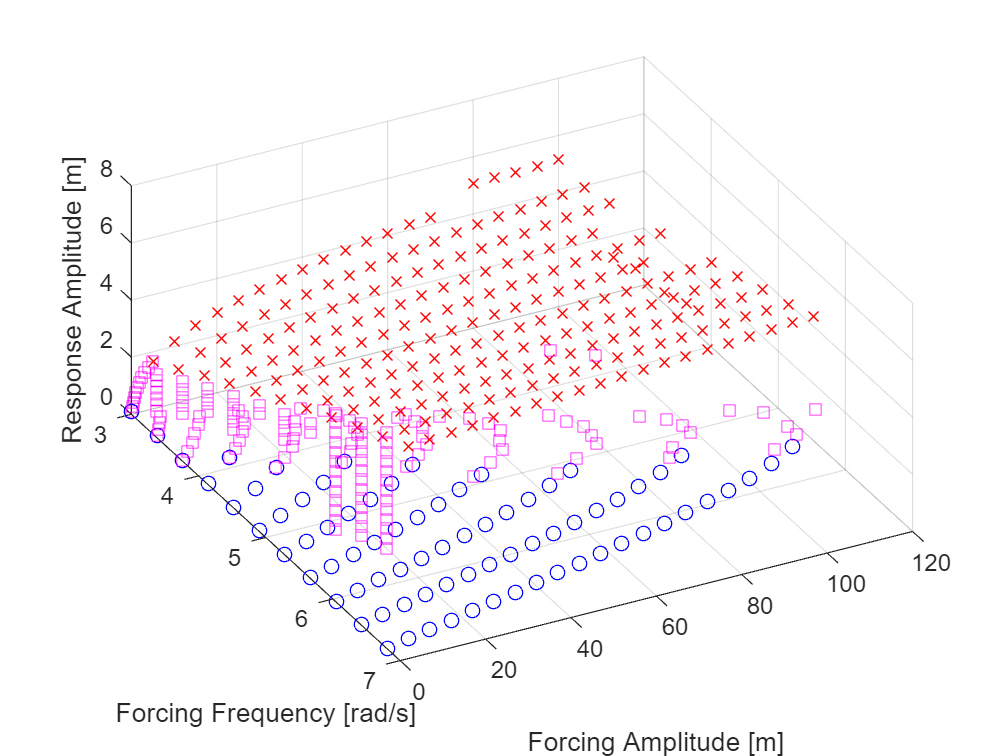

closed_cube = load("closed_cube_save.mat").closed_cube;

% plot all combined
figure;
hold on;
grid on;

for k = (1:length(closed_cube))
    curve = closed_cube{k};

    y1 = curve.up(:, 1);
    z1 = curve.up(:, 2);
    x1 = curve.frequency.*ones(size(y1));

    y2 = curve.down(:, 1);
    z2 = curve.down(:, 2);
    x2 = curve.frequency.*ones(size(y2));
    
    % if k < 7
    y3 = curve.mid(:, 1);
    z3 = curve.mid(:, 2);
    x3 = curve.frequency.*ones(size(y3));
    scatter3(x3, y3, z3, "m", "square");
    % end
    scatter3(x1, y1, z1, "bo");
    scatter3(x2, y2, z2, "rx");
end
view([73.00 23.59]);
xlabel("Forcing Frequency [rad/s]");
ylabel("Forcing Amplitude [m]");
% ylim([1, Inf])

zlabel("Response Amplitude [m]");